# Smith et al. - Interacting Adaptive Processes with Different Timescales Underlie Short-Term Motor Learning (2006)

clear; clc;
cd('/Users/duncan/Documents/GitHub/Recreate-Papers/Smith_2state')

## Perturbation Schedules

% paradigm for relearning experiment 
sched1 = zeros([800,1]);
sched1(50:400) = 1;
sched1(401:425) = -1;
sched1(426:800) = 1; 
% relearning experiment with washout 
sched2 = zeros([1000, 1]);
sched2(50:400) = 1;
sched2(401:425) = -1;
sched2(426:600) = 0;
sched2(601:1000) = 1; 
% paradigm for error-clamp experiment 
sched3 = zeros([800,1]);
sched3(50:400) = 1;
sched3(401:425) = -1;
sched3(426:800) = nan; 
% error-clamp / relearning experiment 
sched4 = zeros([800,1]);
sched4(50:400) = 1;
sched4(401:425) = -1;
sched4(426:500) = nan; 
sched4(501:800) = 1; 

## Model Performance

### Paradigm for Relearning Experiment 

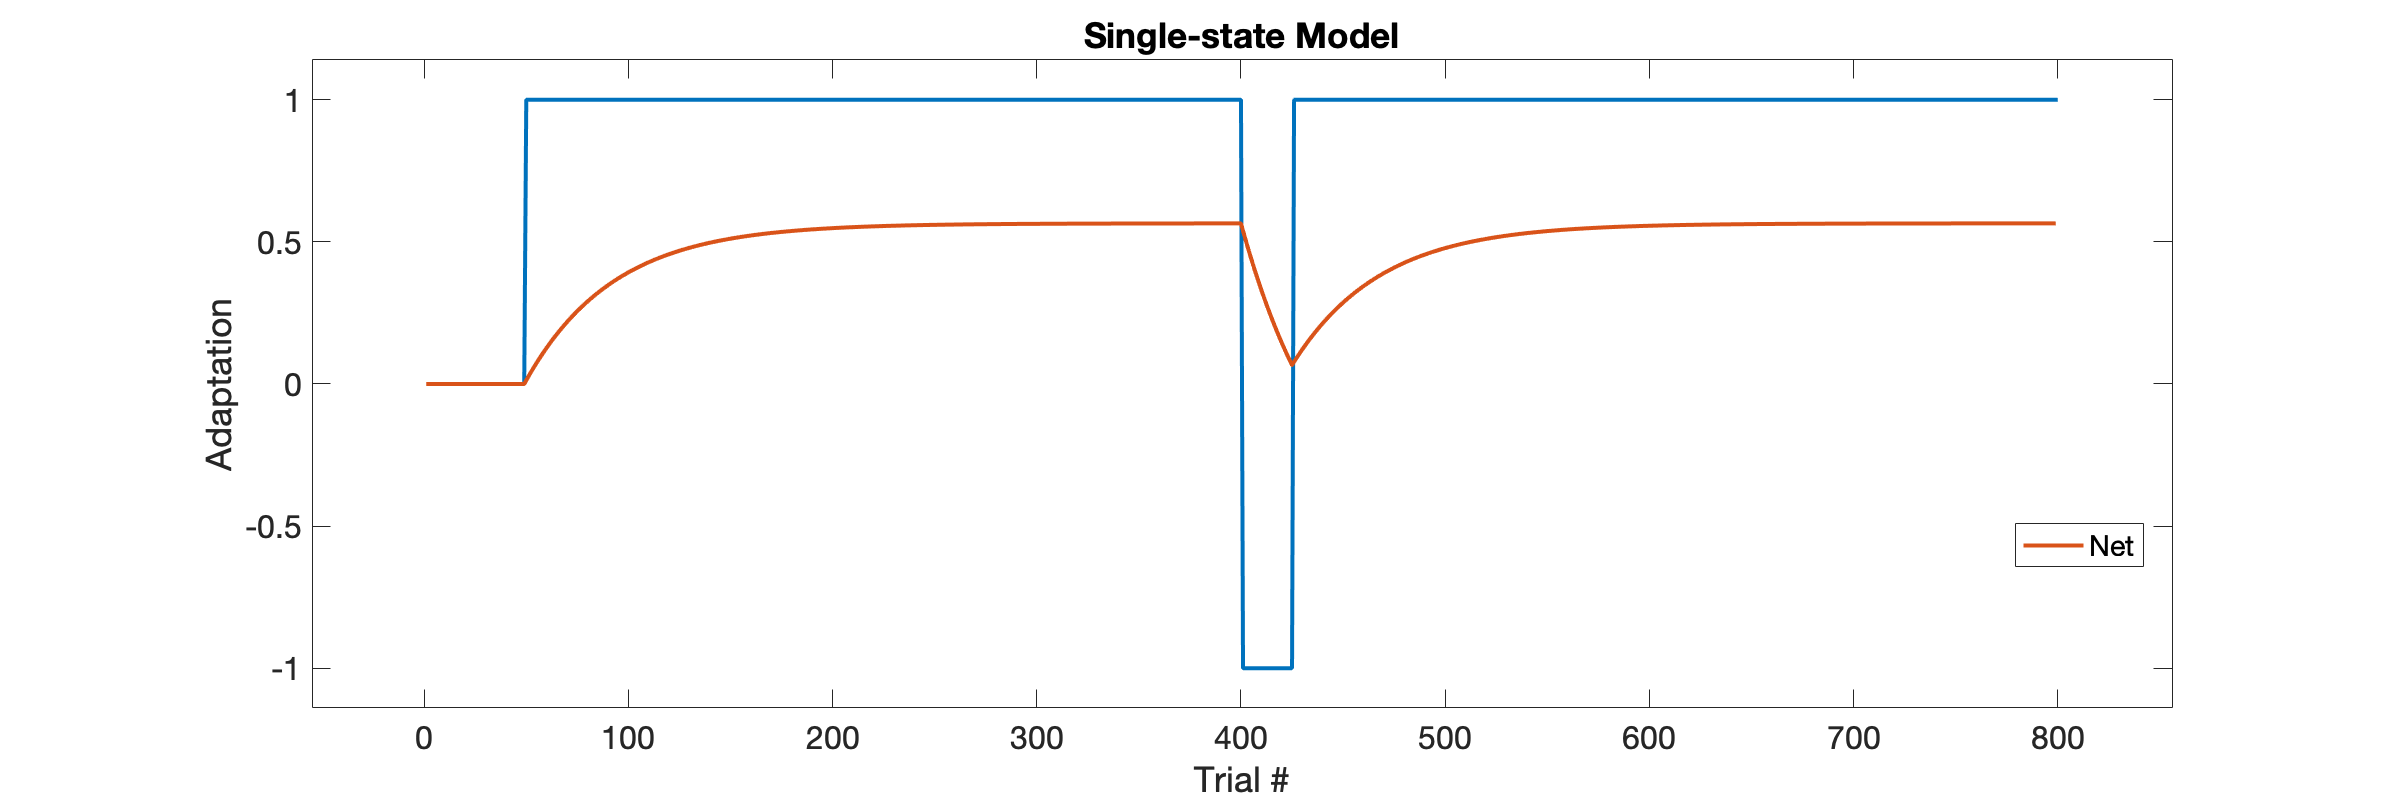

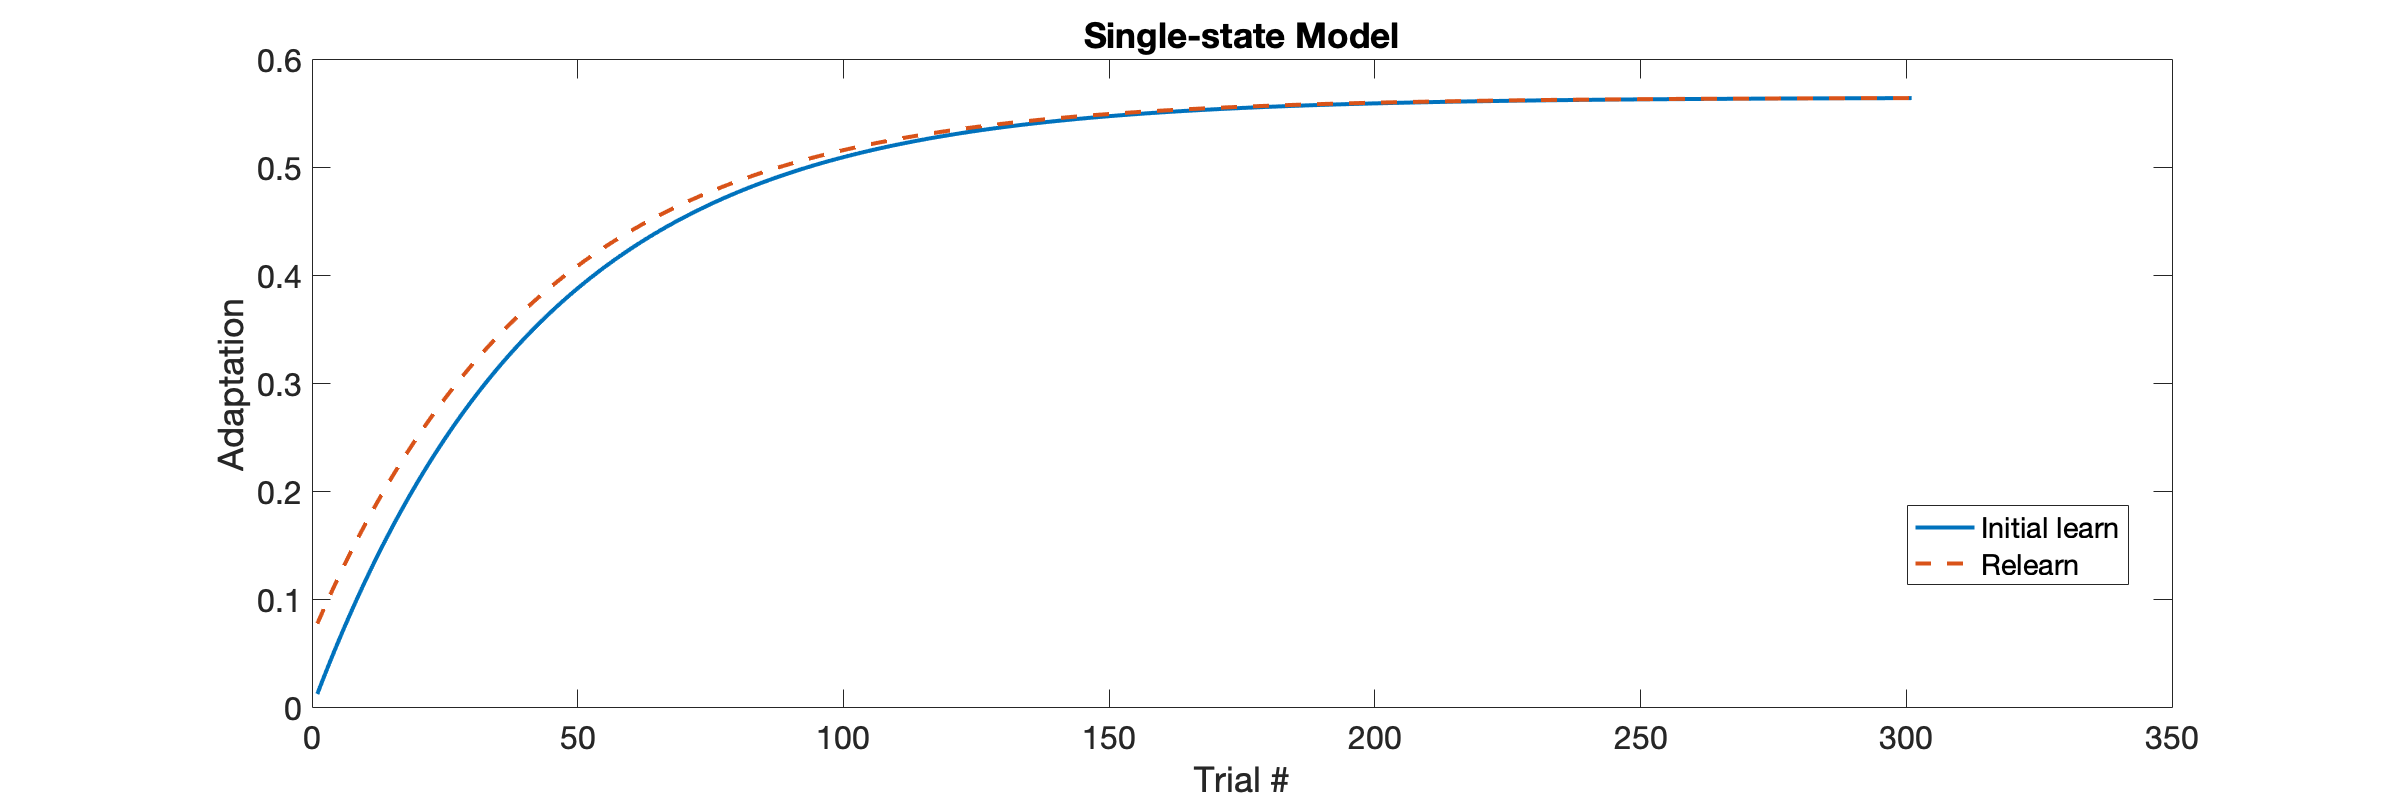

% single_state(sched1)
% gain_specific(sched1)
% multi_rate(sched1)
single_state(sched1, 'plotSavings', true)

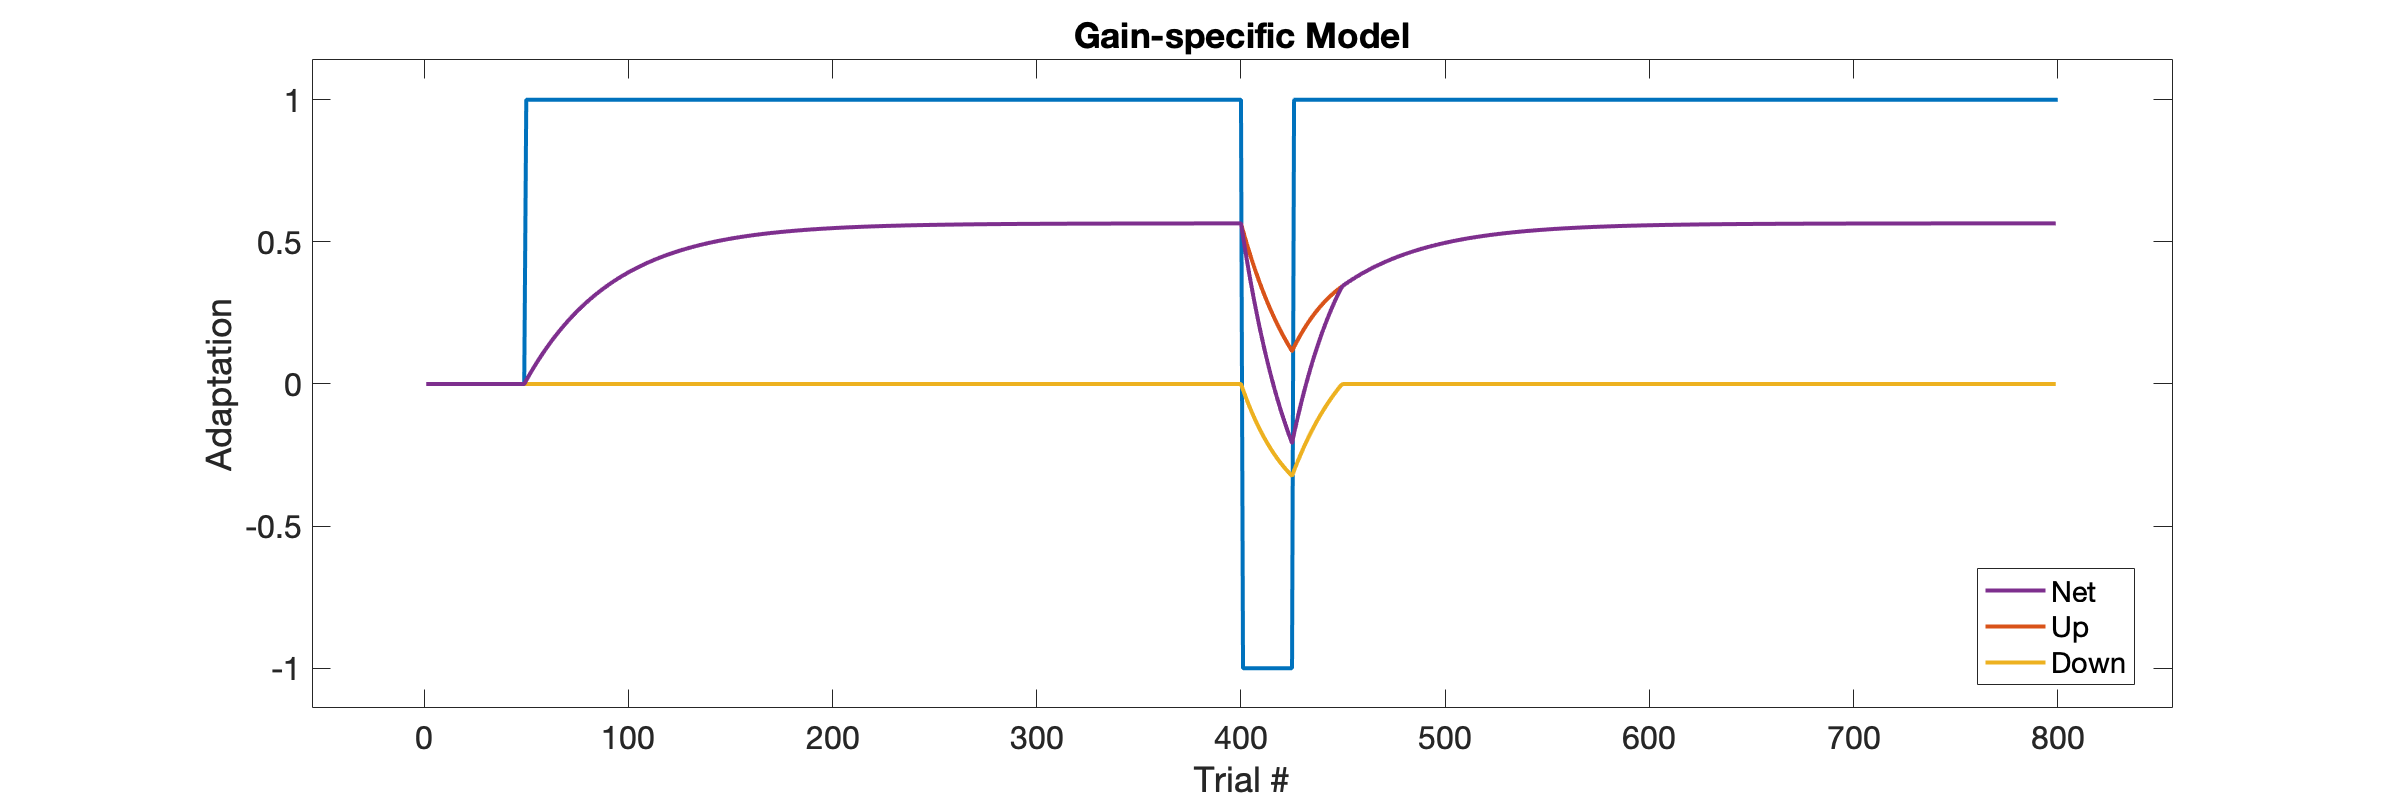

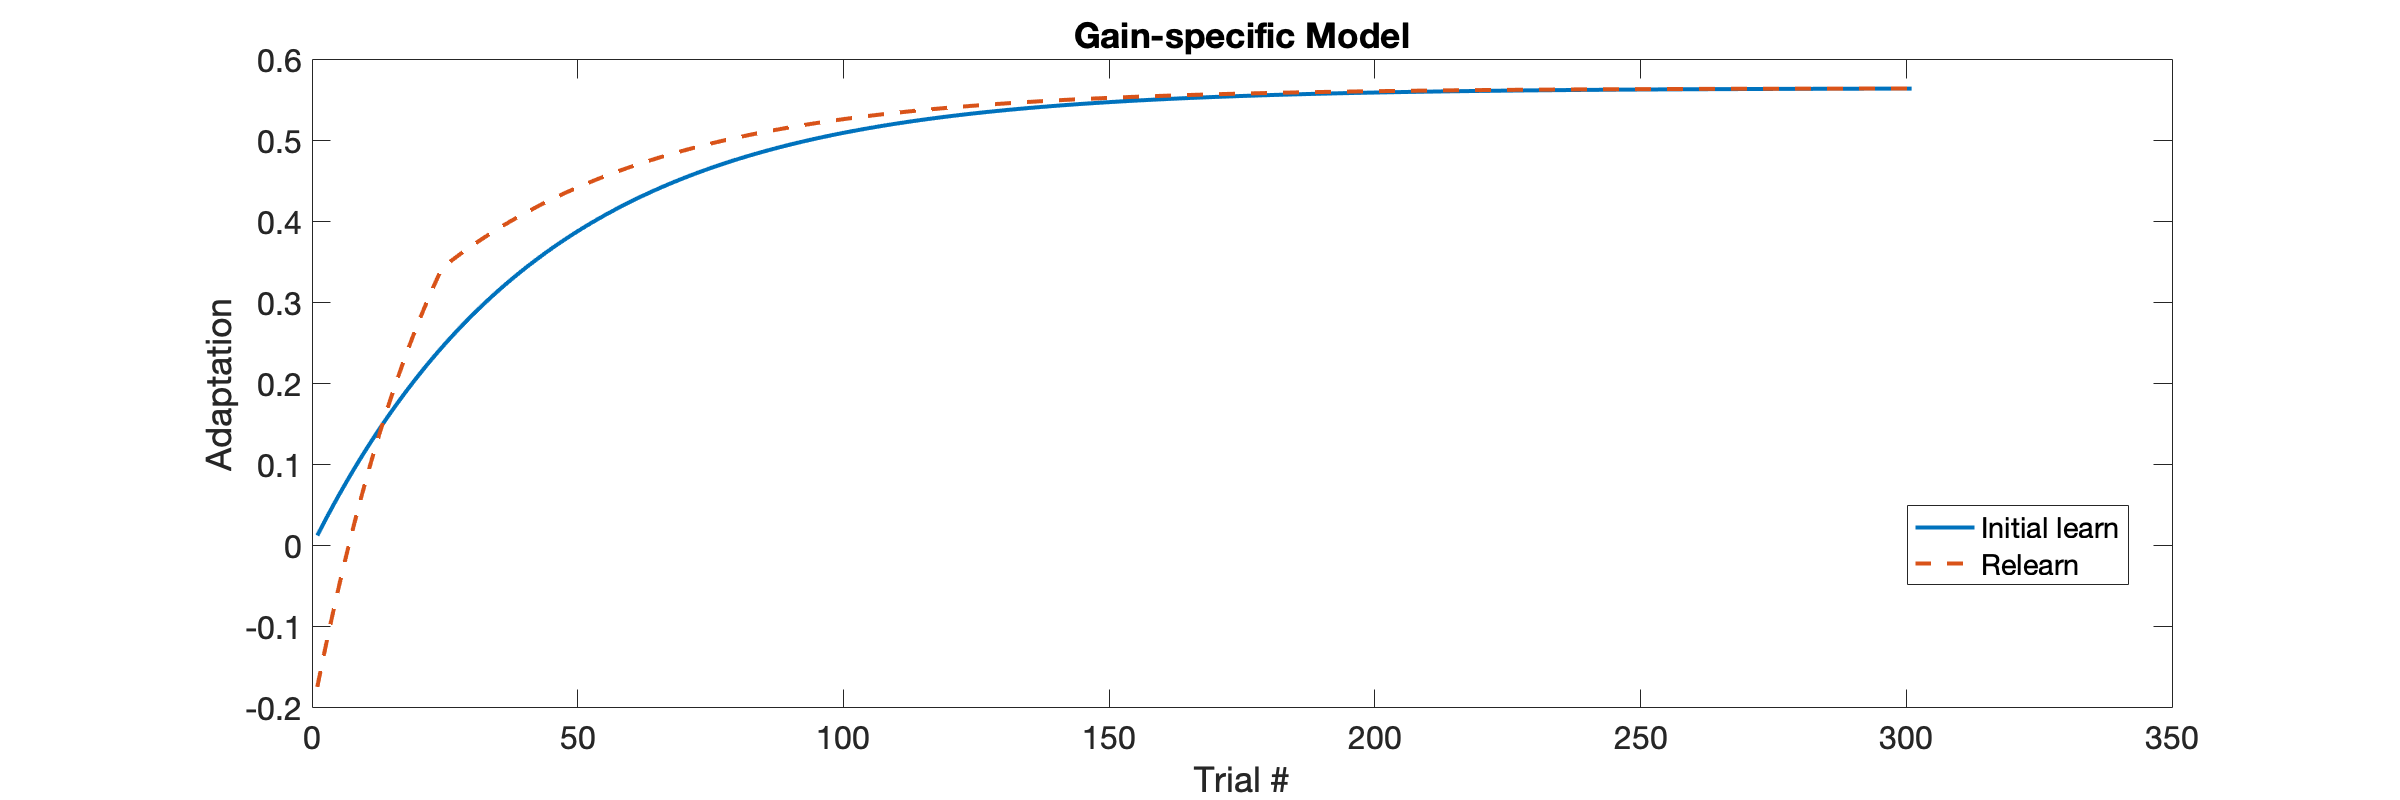

gain_specific(sched1, 'plotSavings', true)

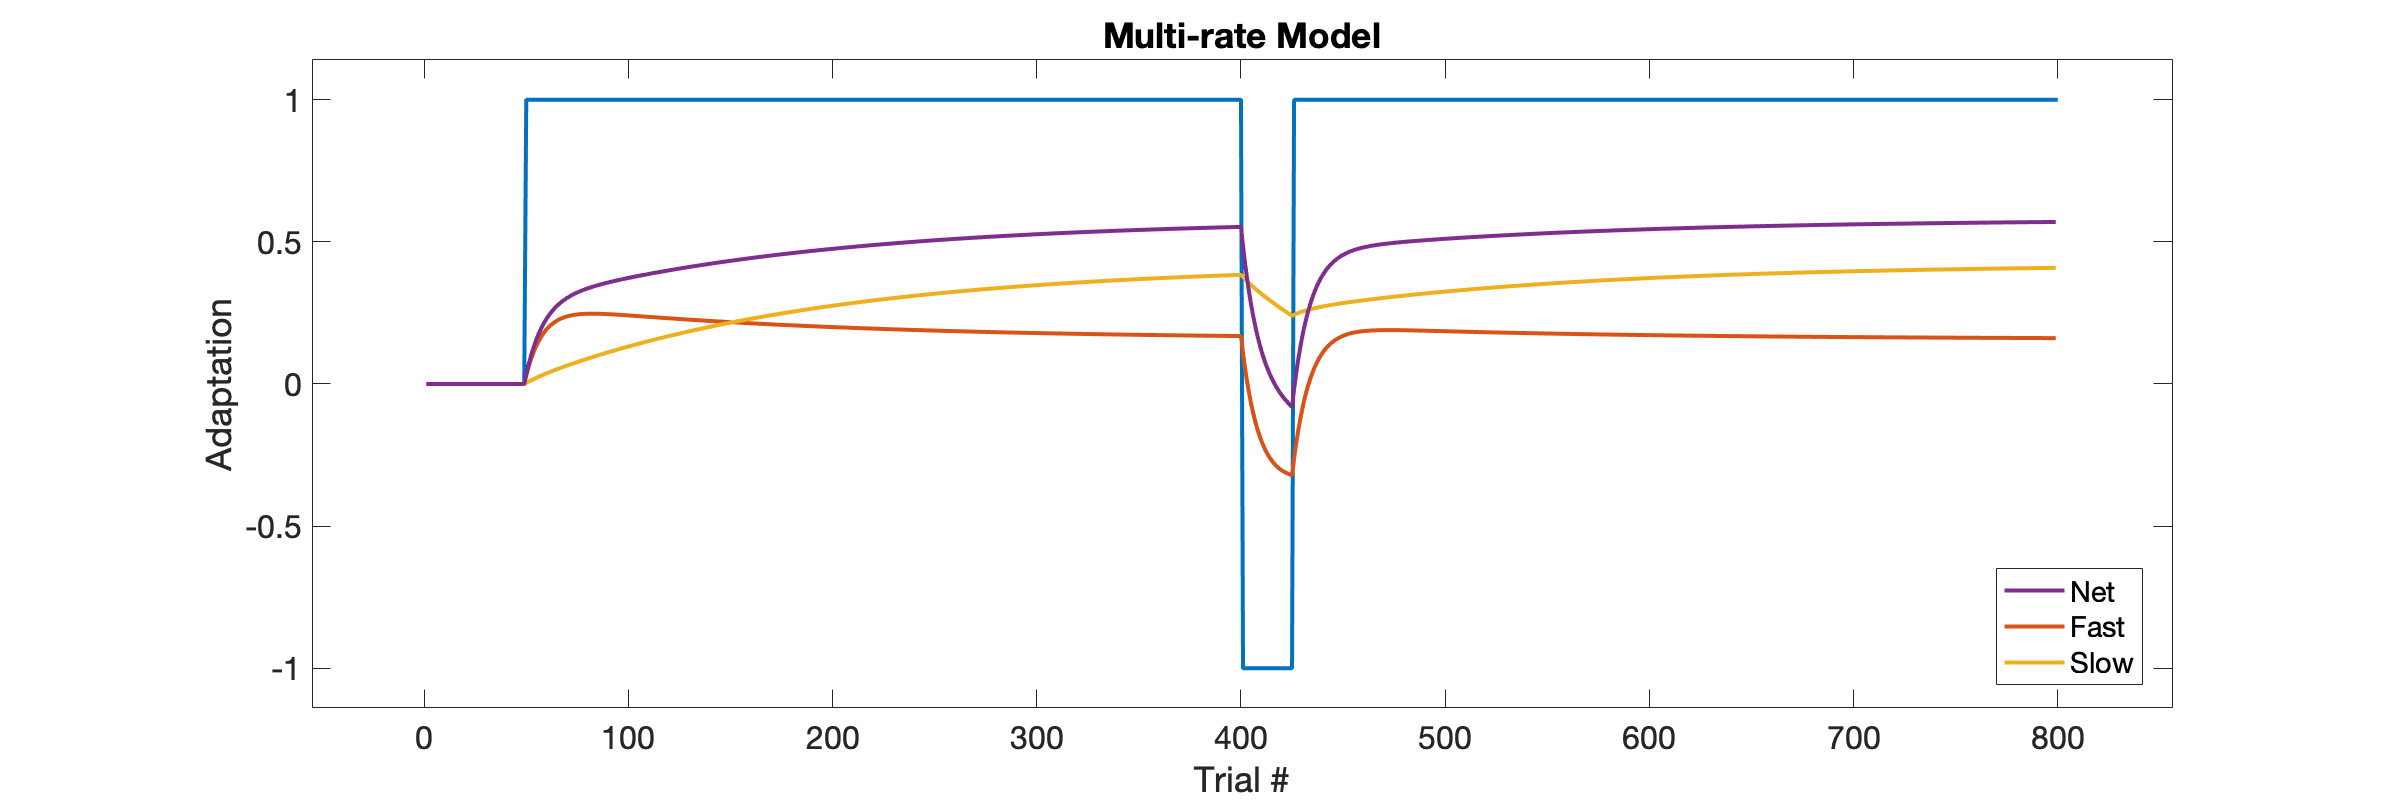

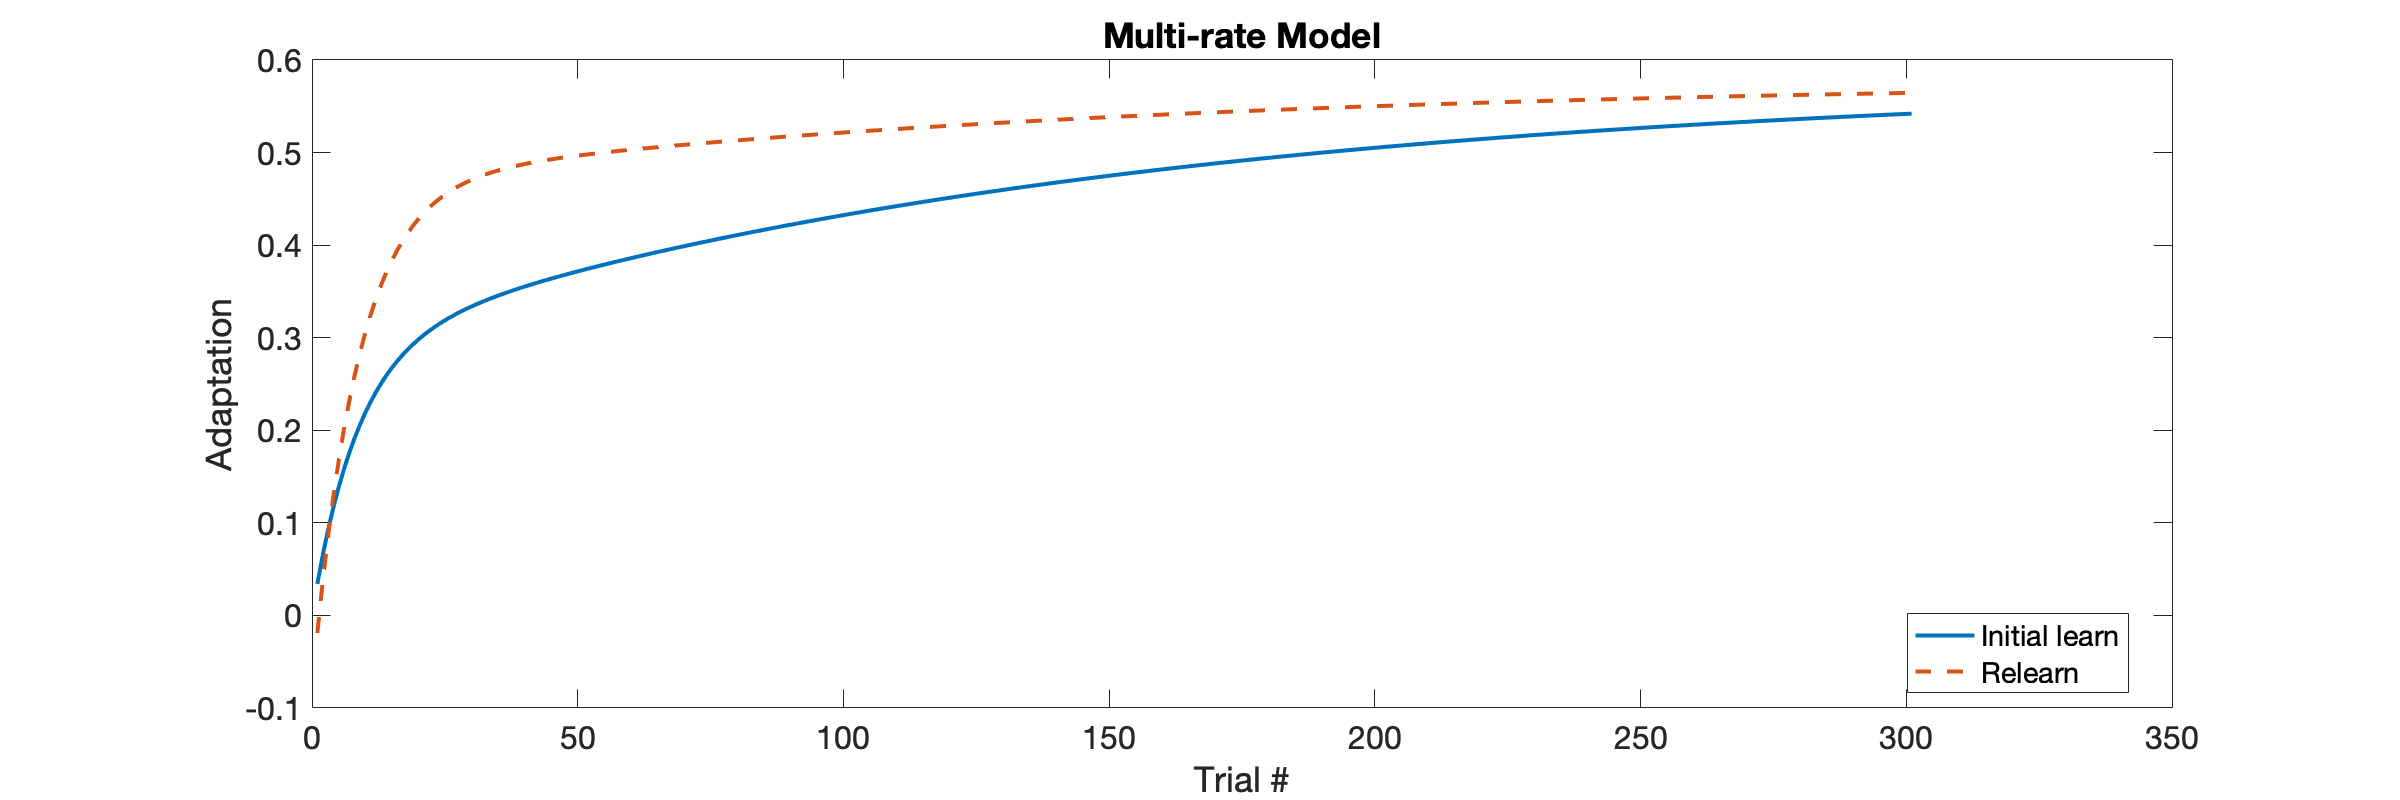

multi_rate(sched1, 'plotSavings', true)

### Relearning experiment with washout 

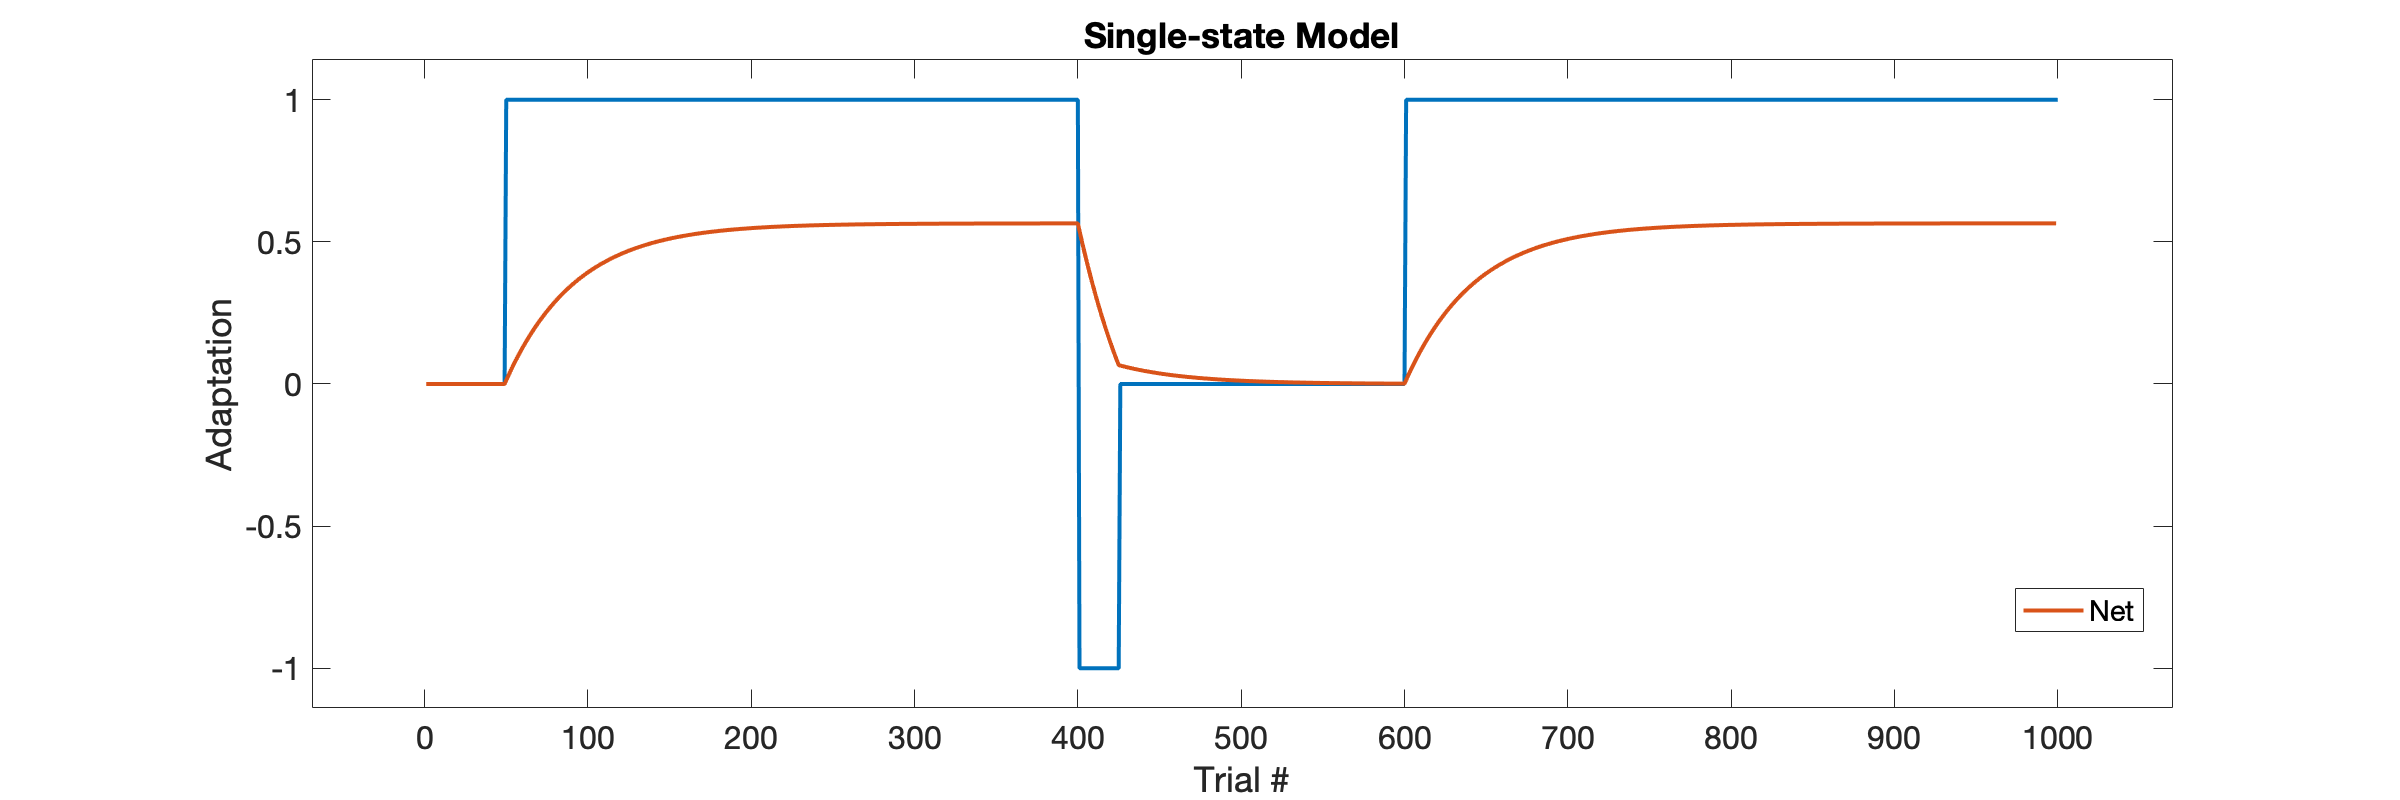

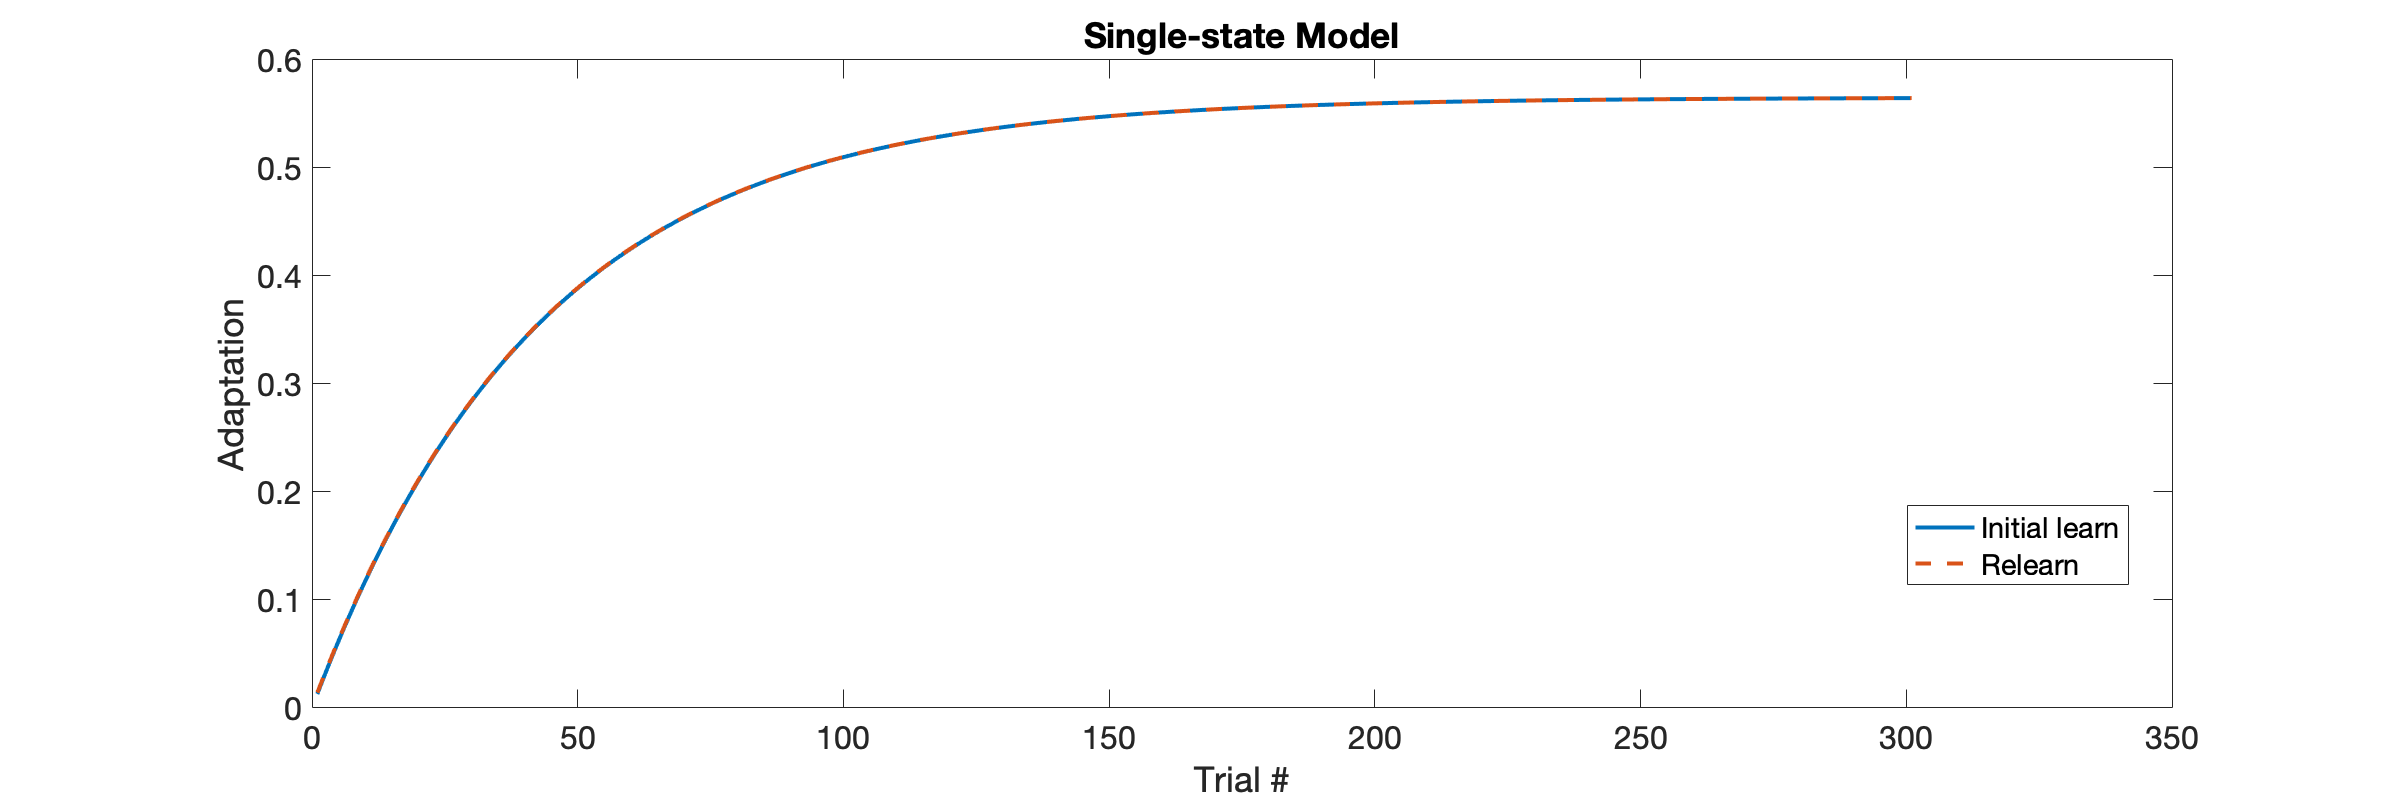

% single_state(sched2)
% gain_specific(sched2)
% multi_rate(sched2)
single_state(sched2, 'plotSavings', true)

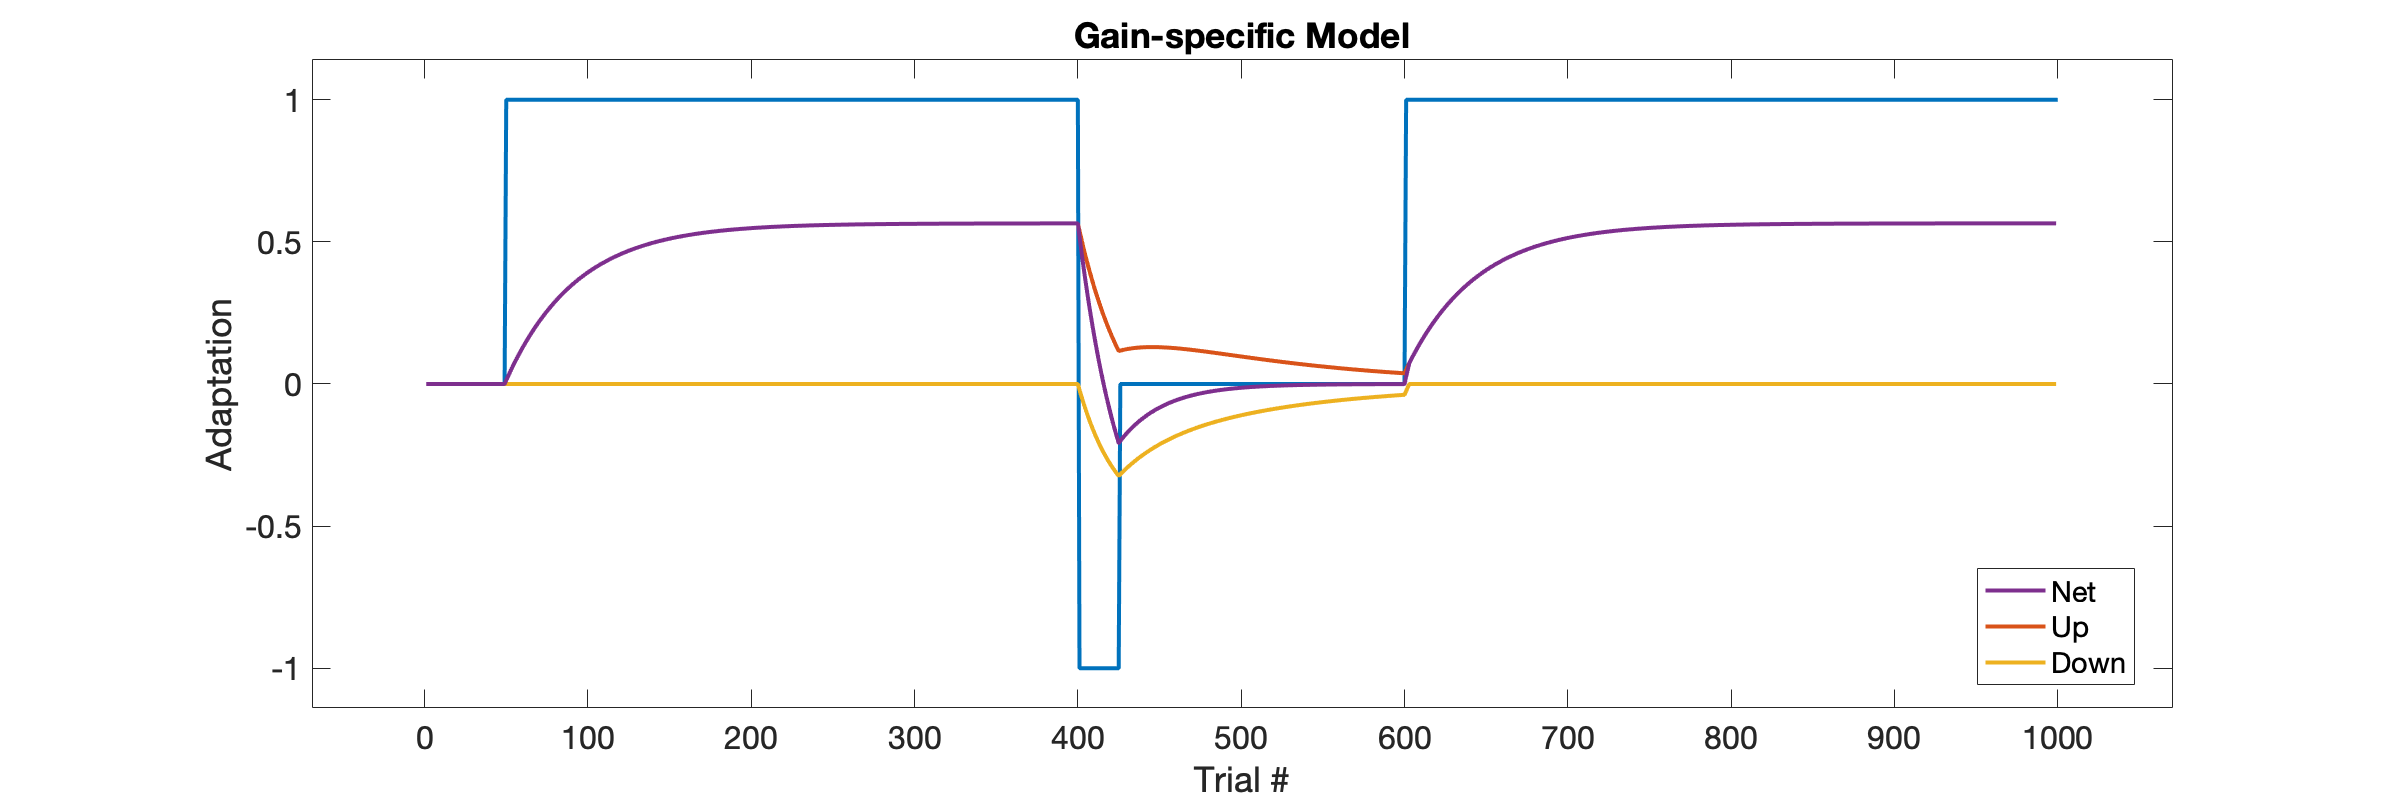

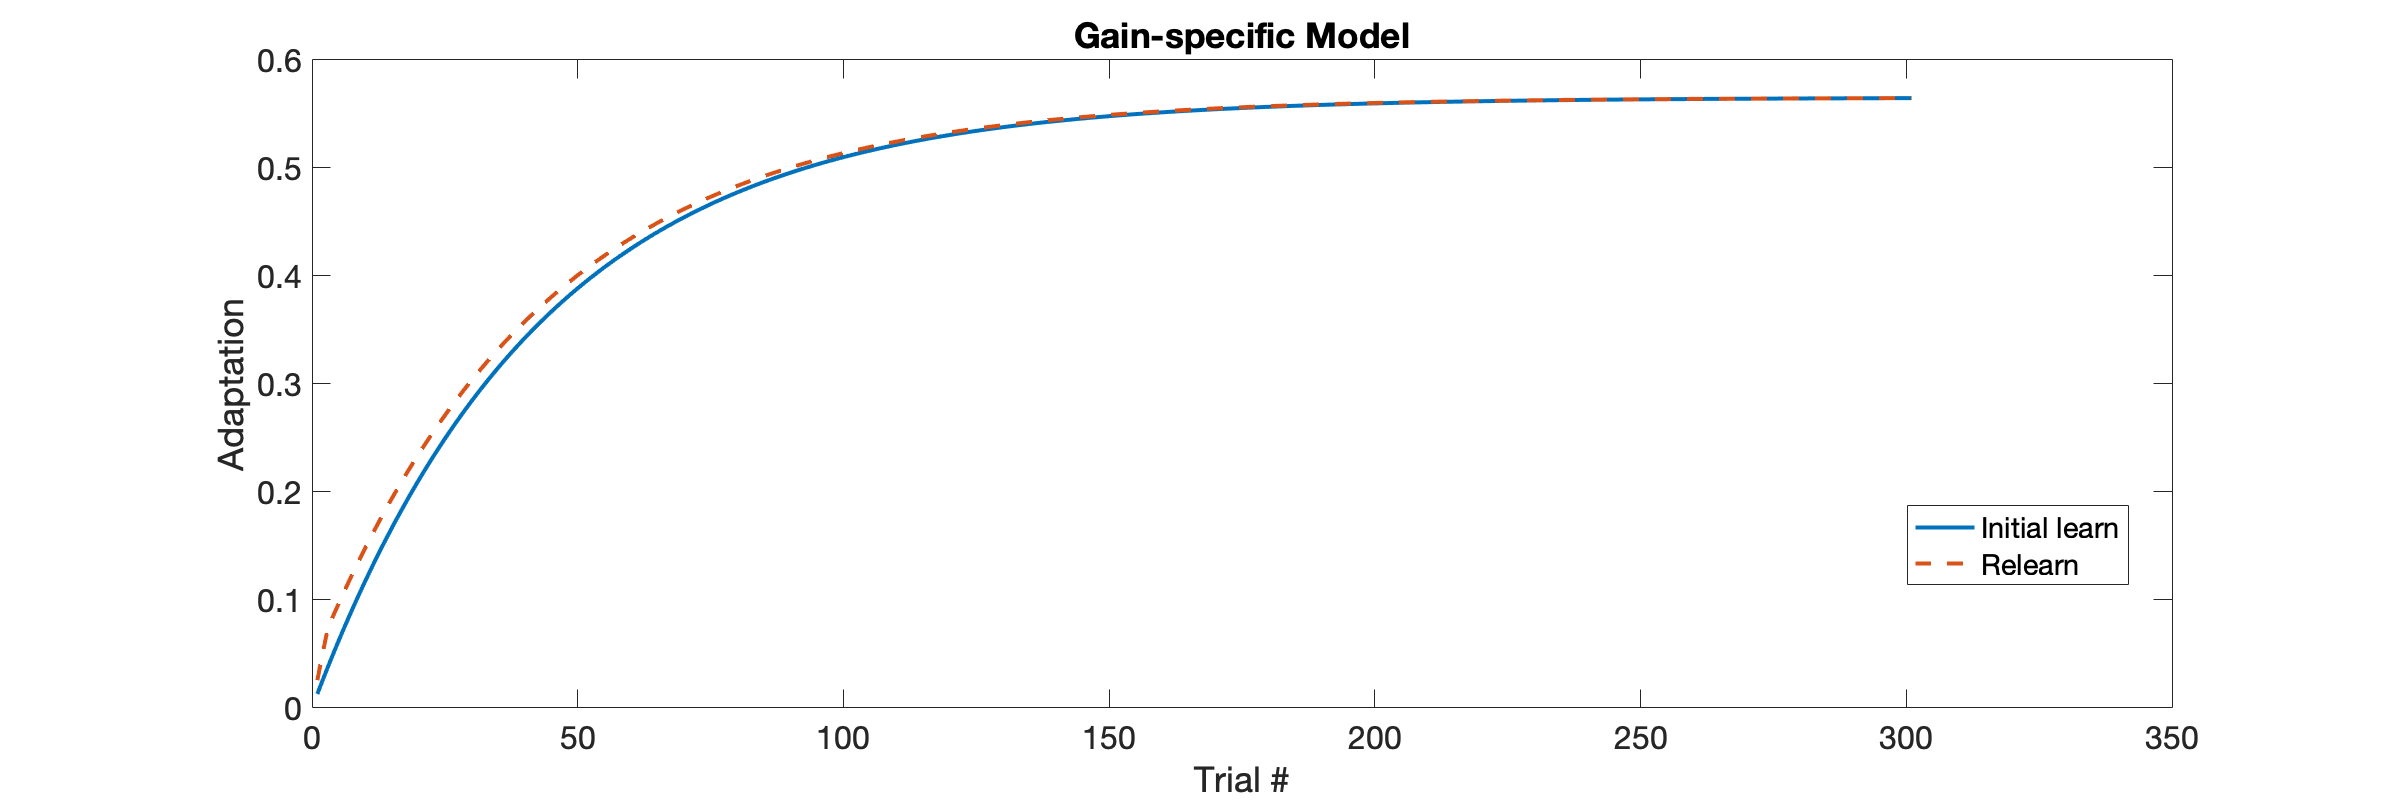

gain_specific(sched2, 'plotSavings', true)

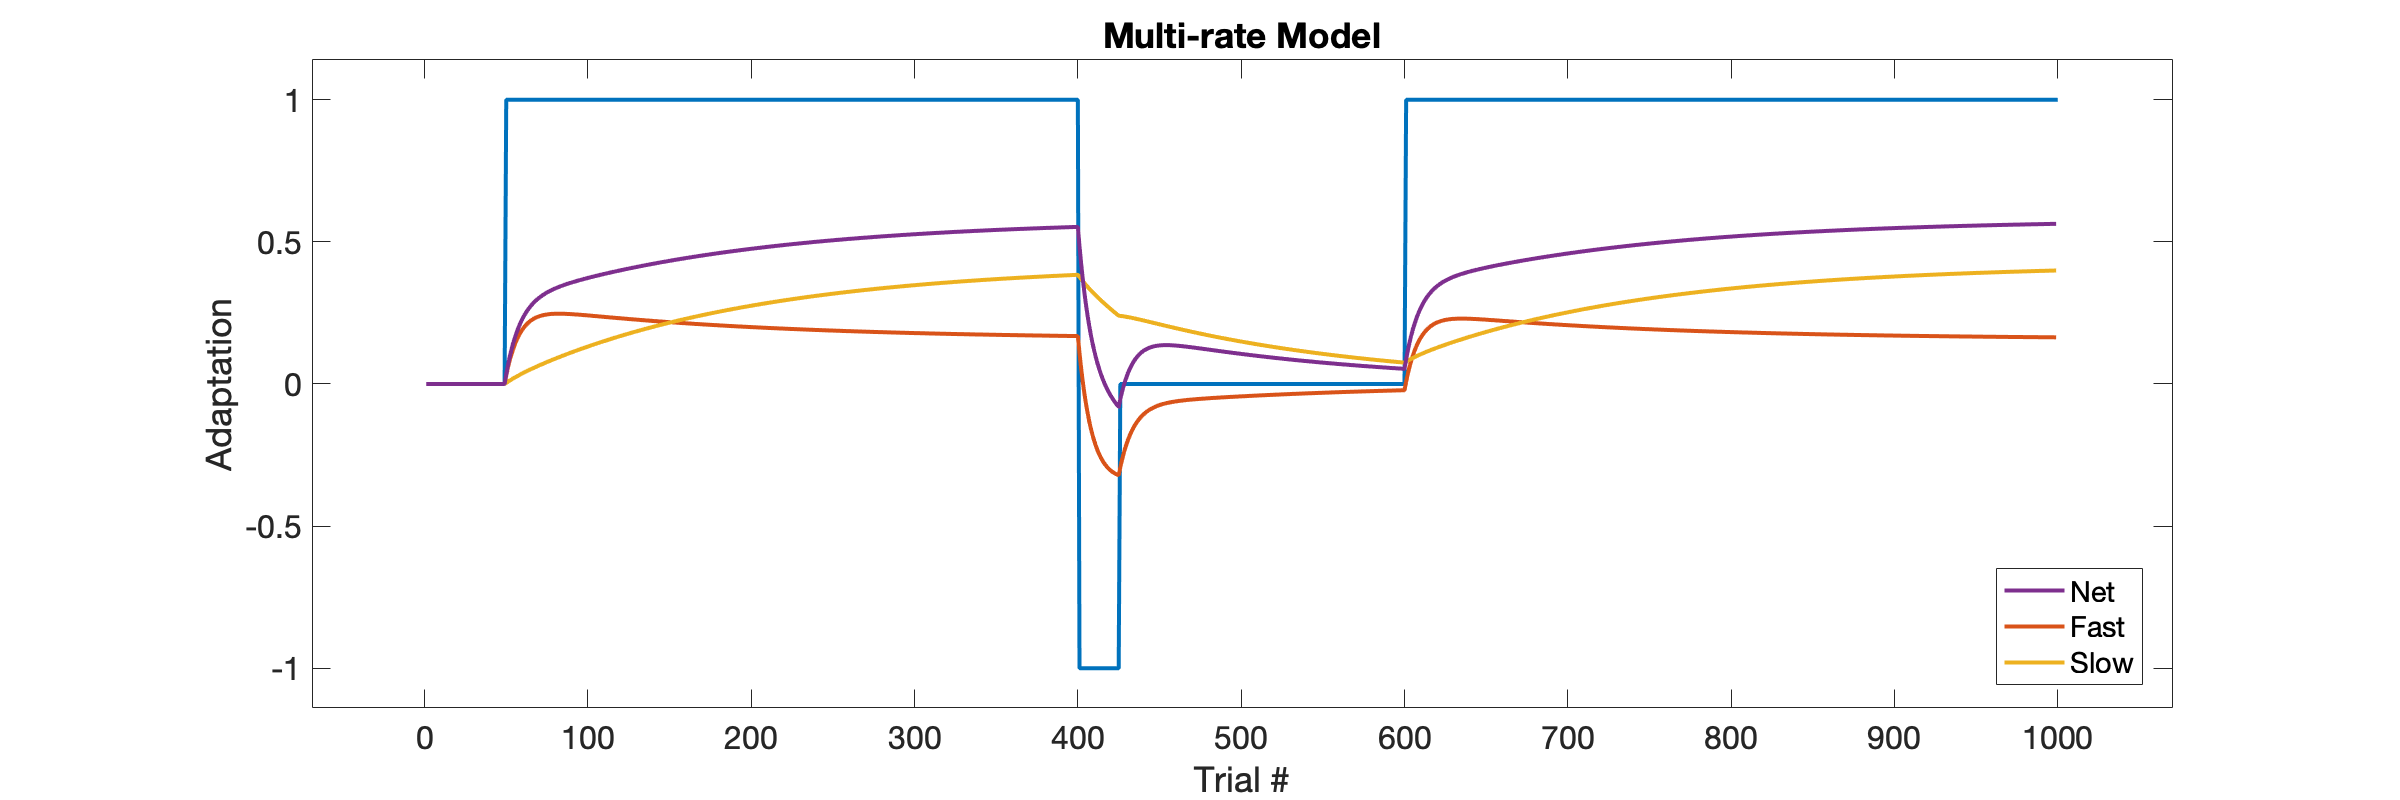

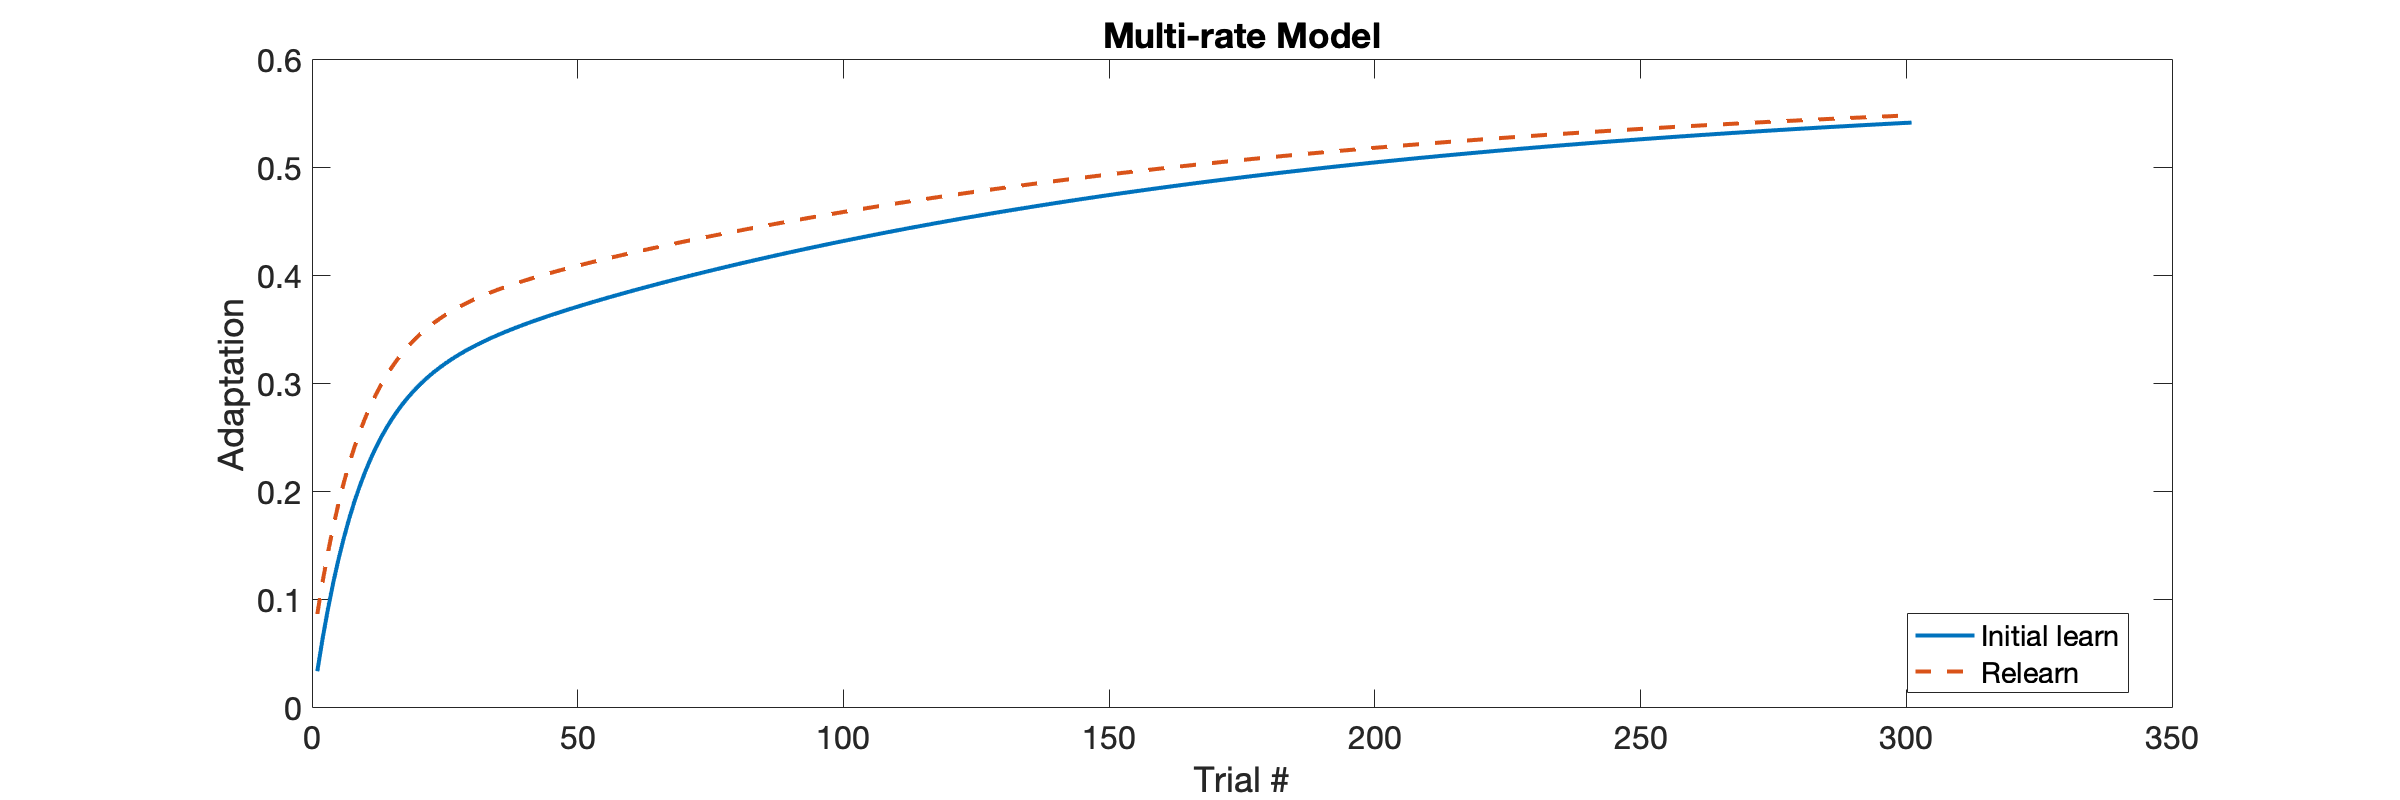

multi_rate(sched2, 'plotSavings', true)

### Paradigm for Error-Clamp Experiment 

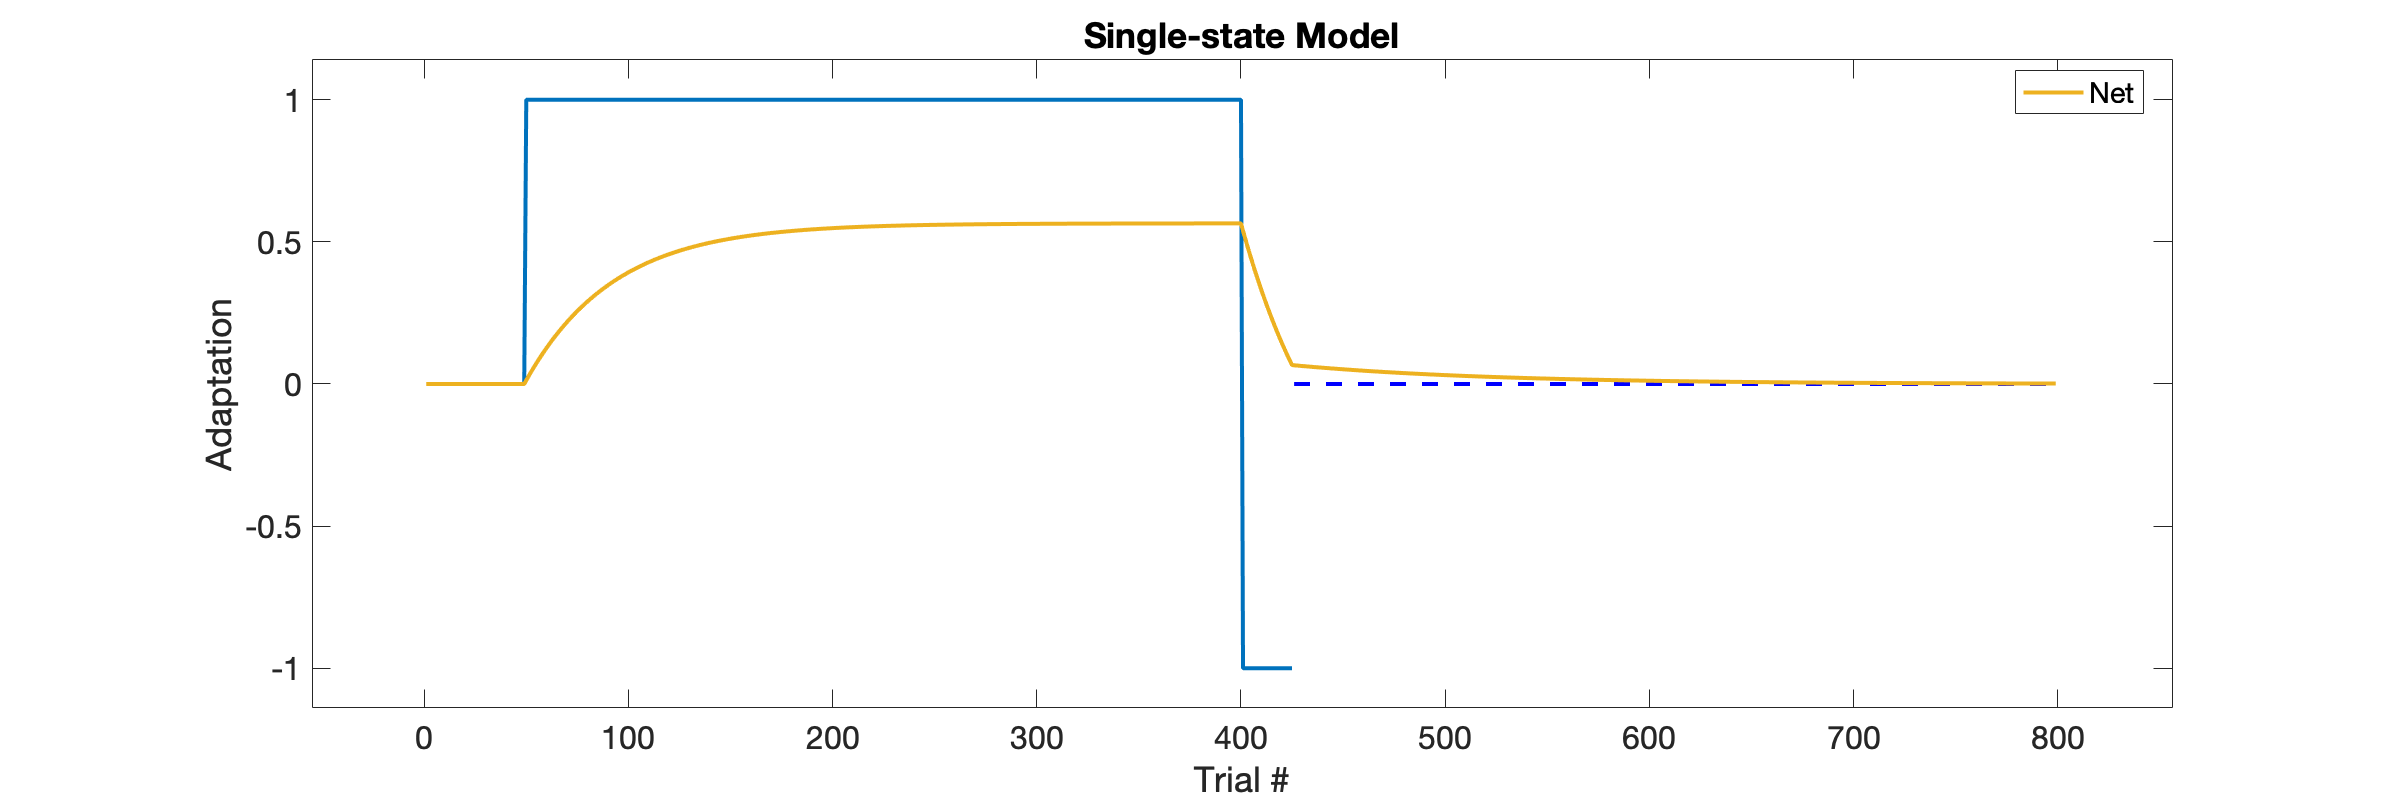

single_state(sched3)

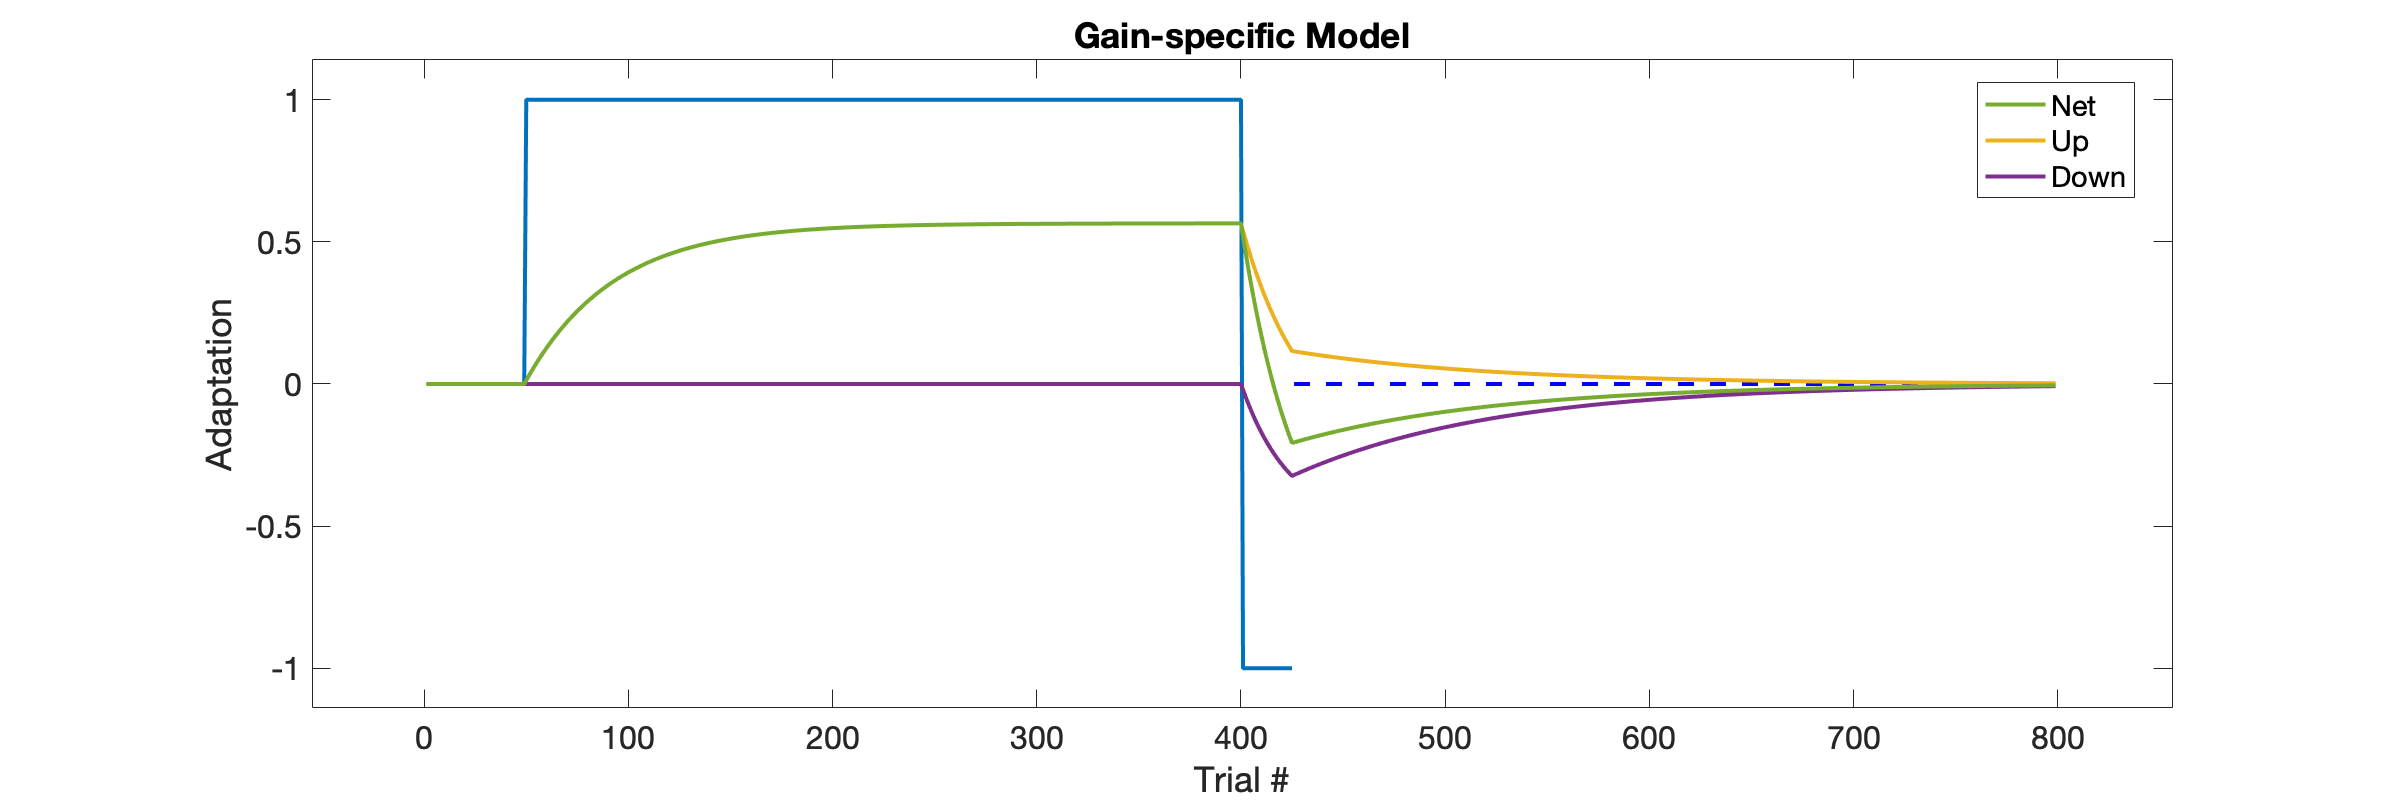

gain_specific(sched3)

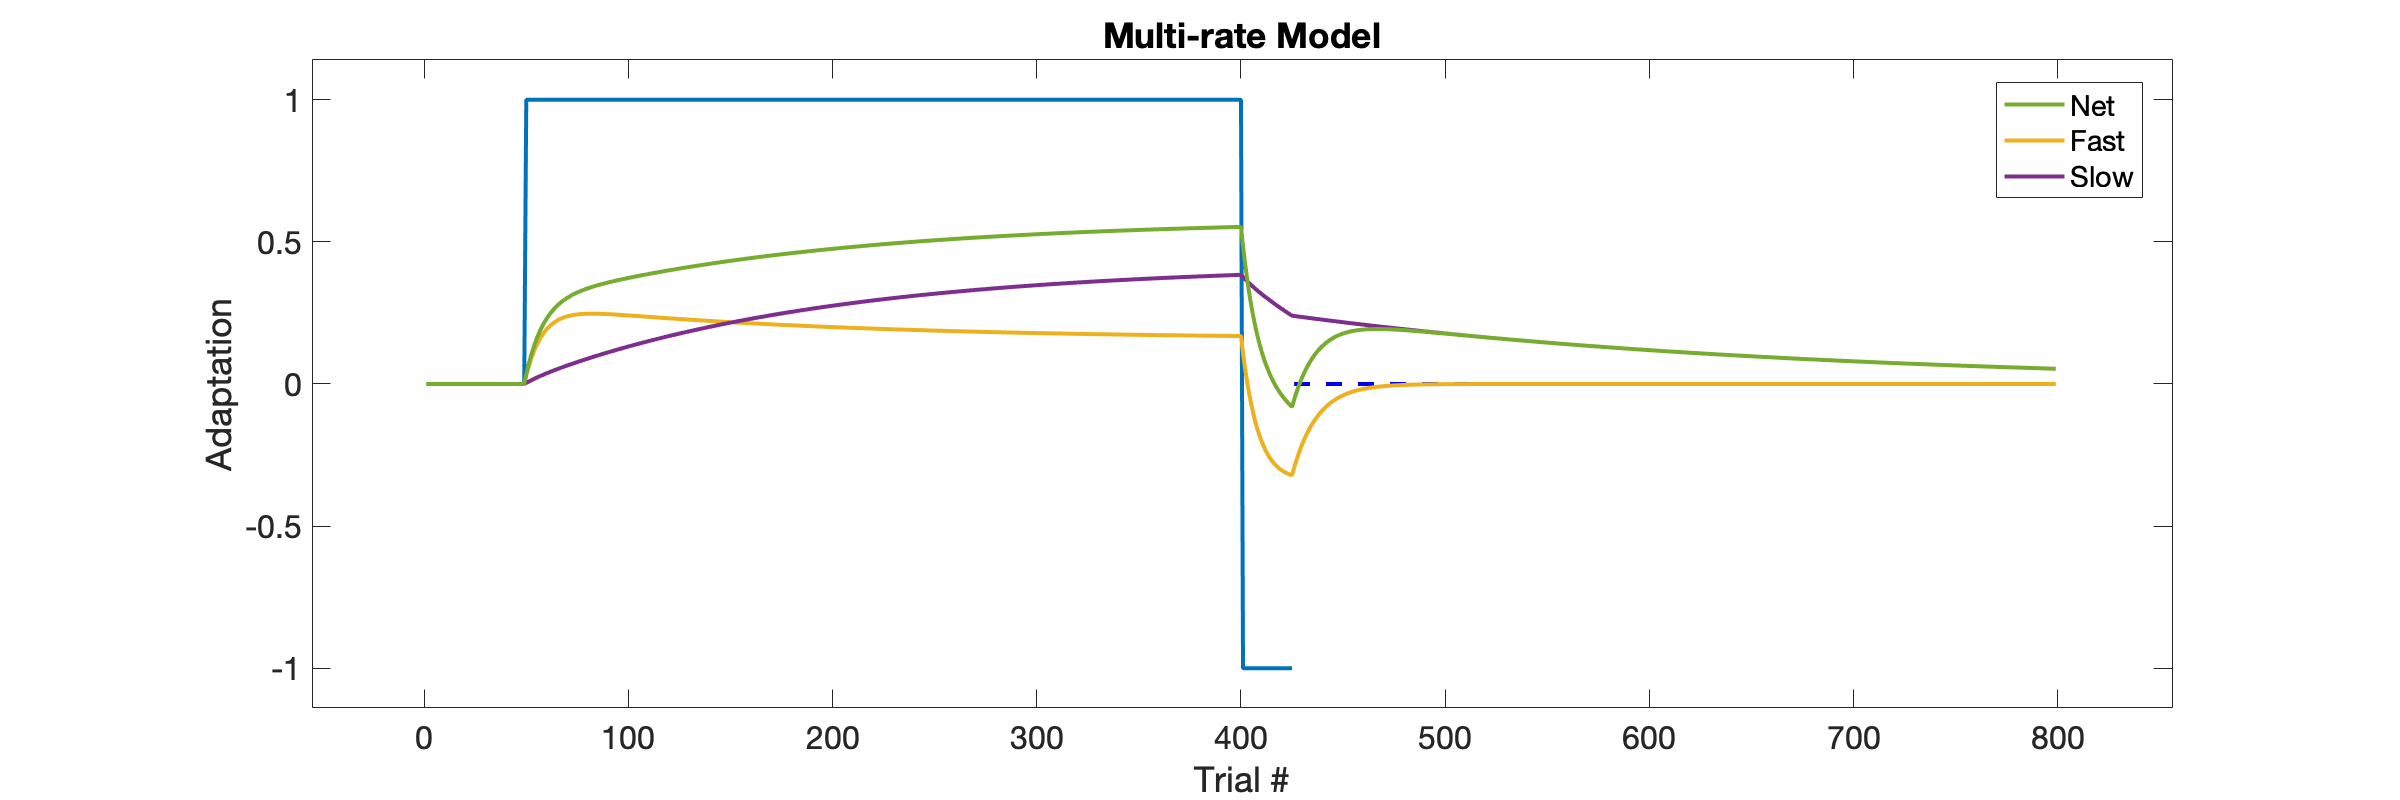

multi_rate(sched3)

### Error-Clamp / Relearning Experiment 

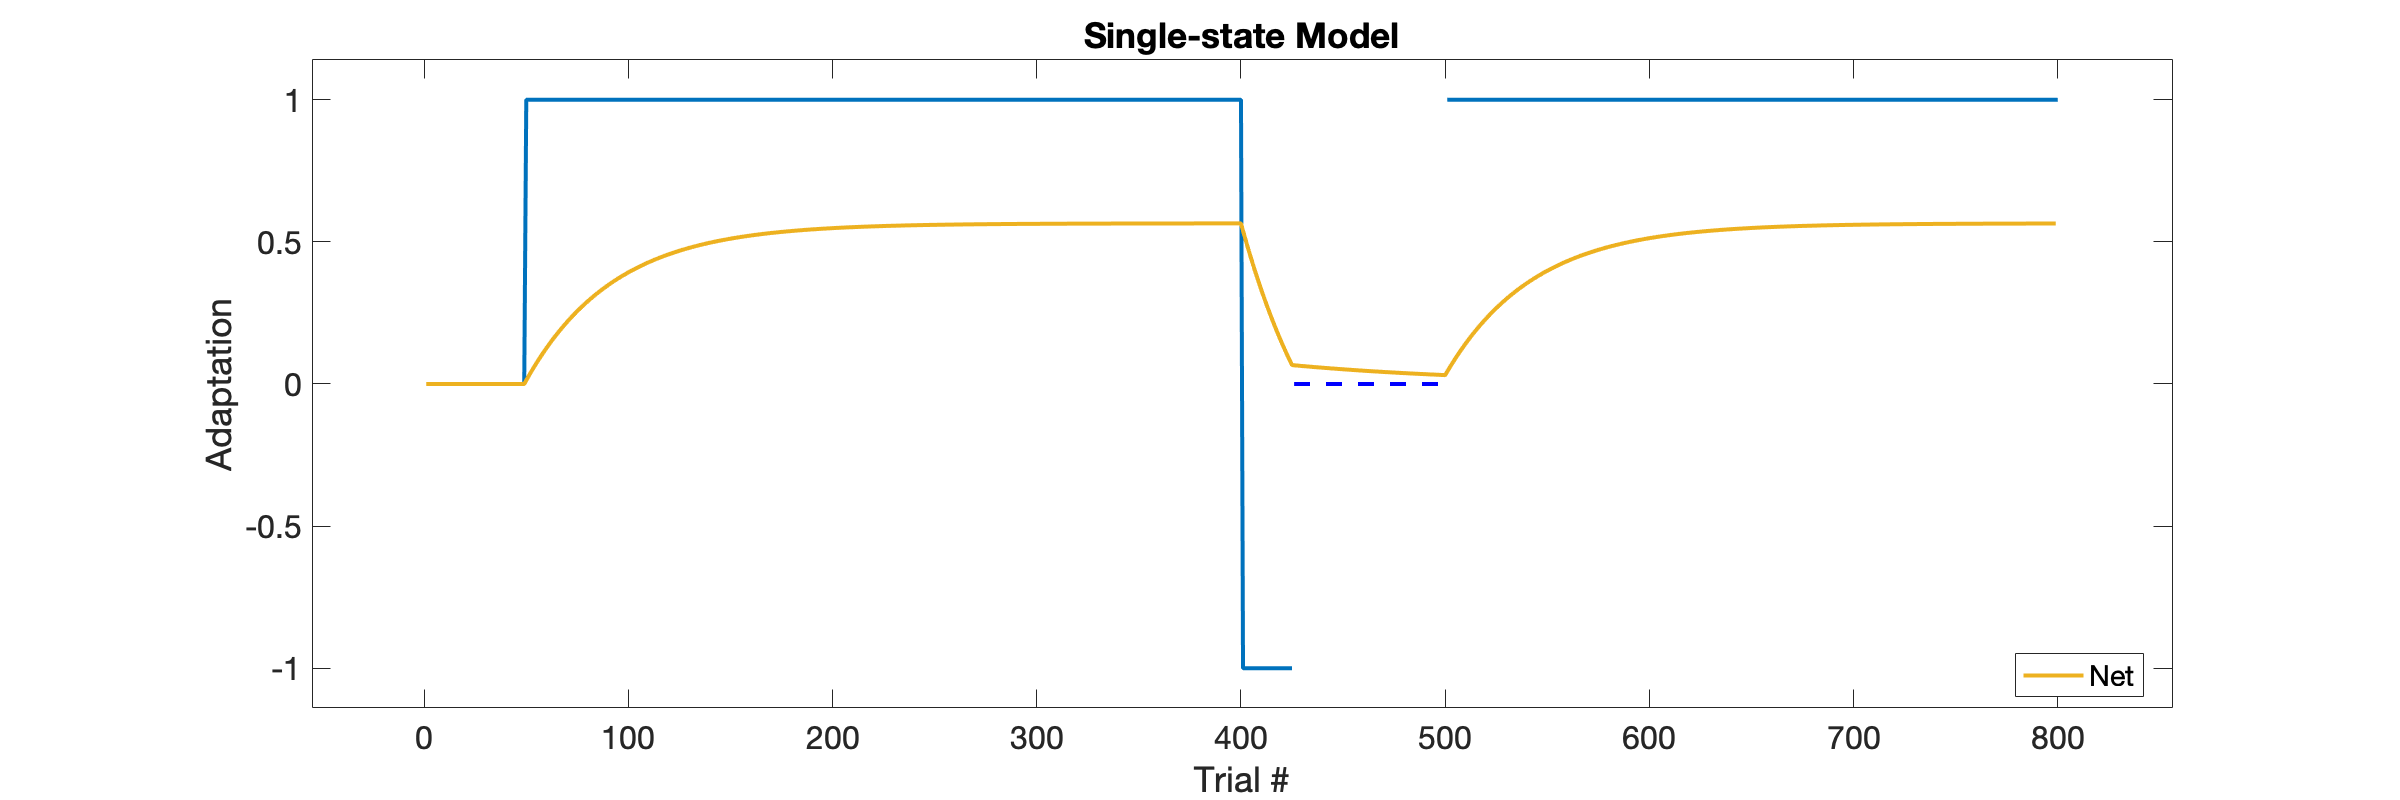

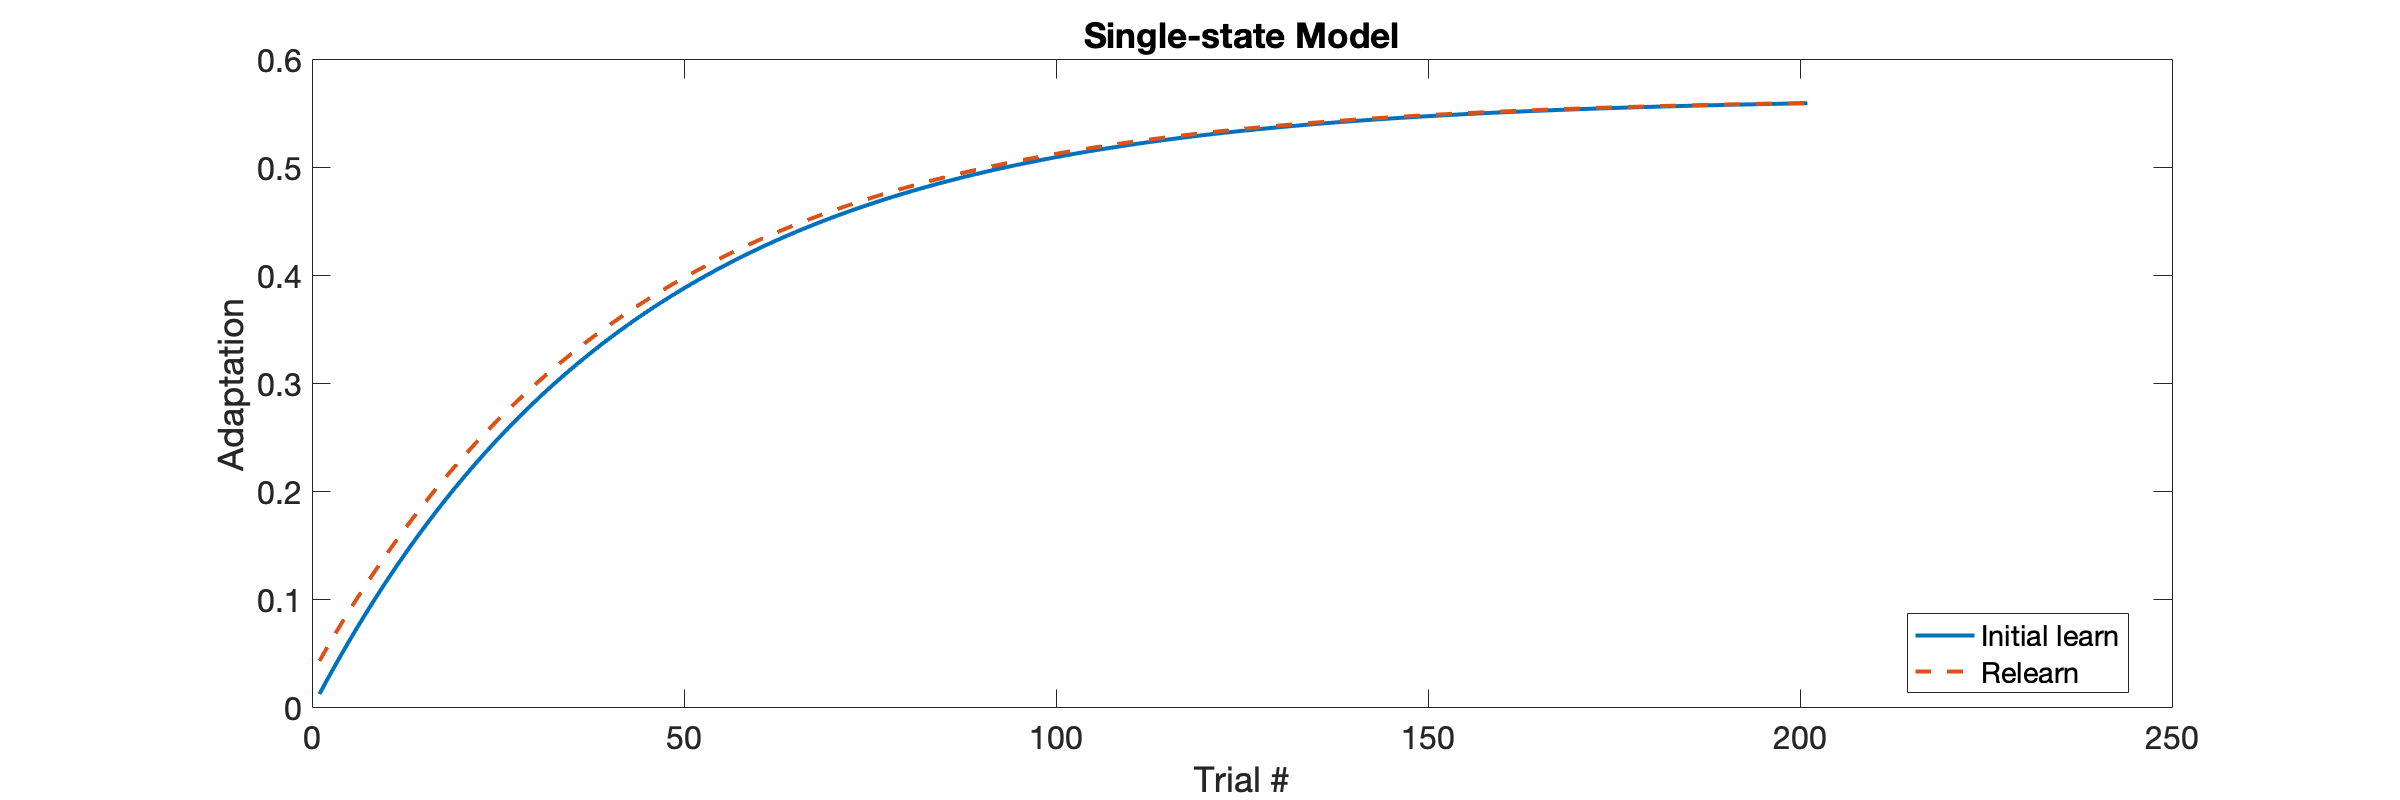

% single_state(sched4)
% gain_specific(sched4)
% multi_rate(sched4)
single_state(sched4, 'plotSavings', true, 'savingsLen', 200)

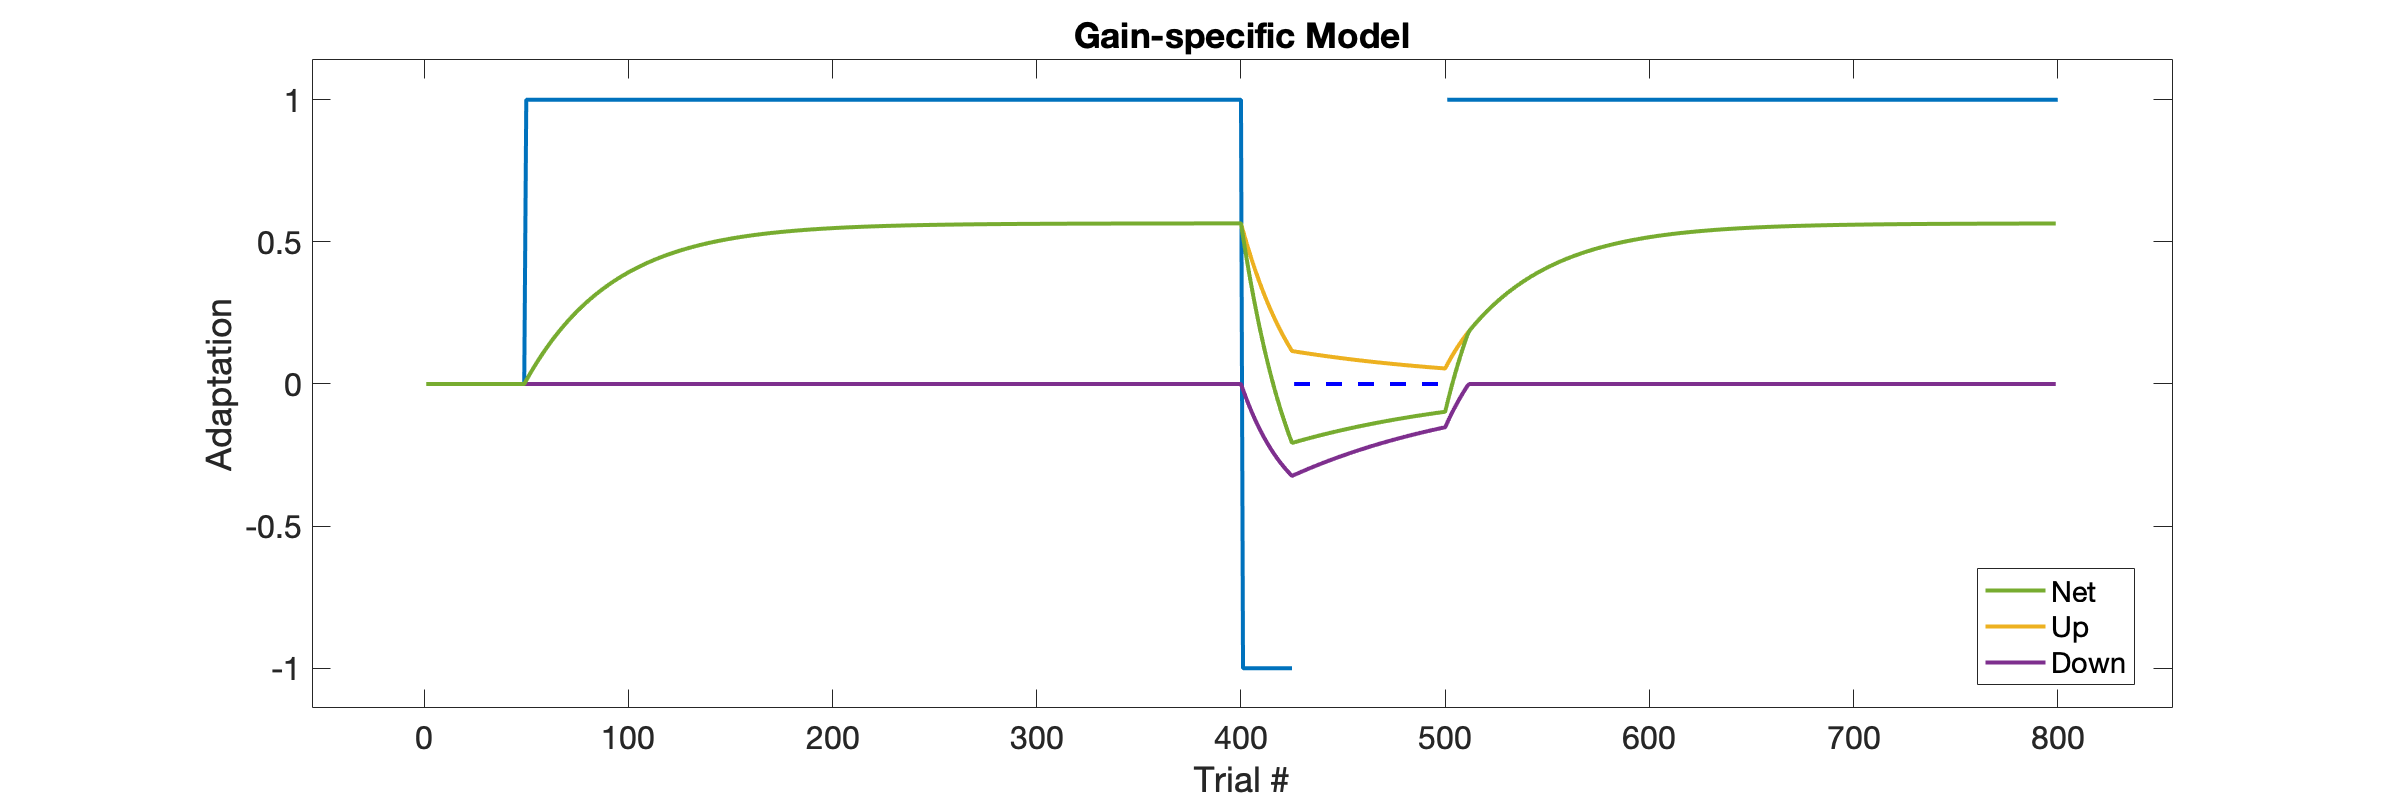

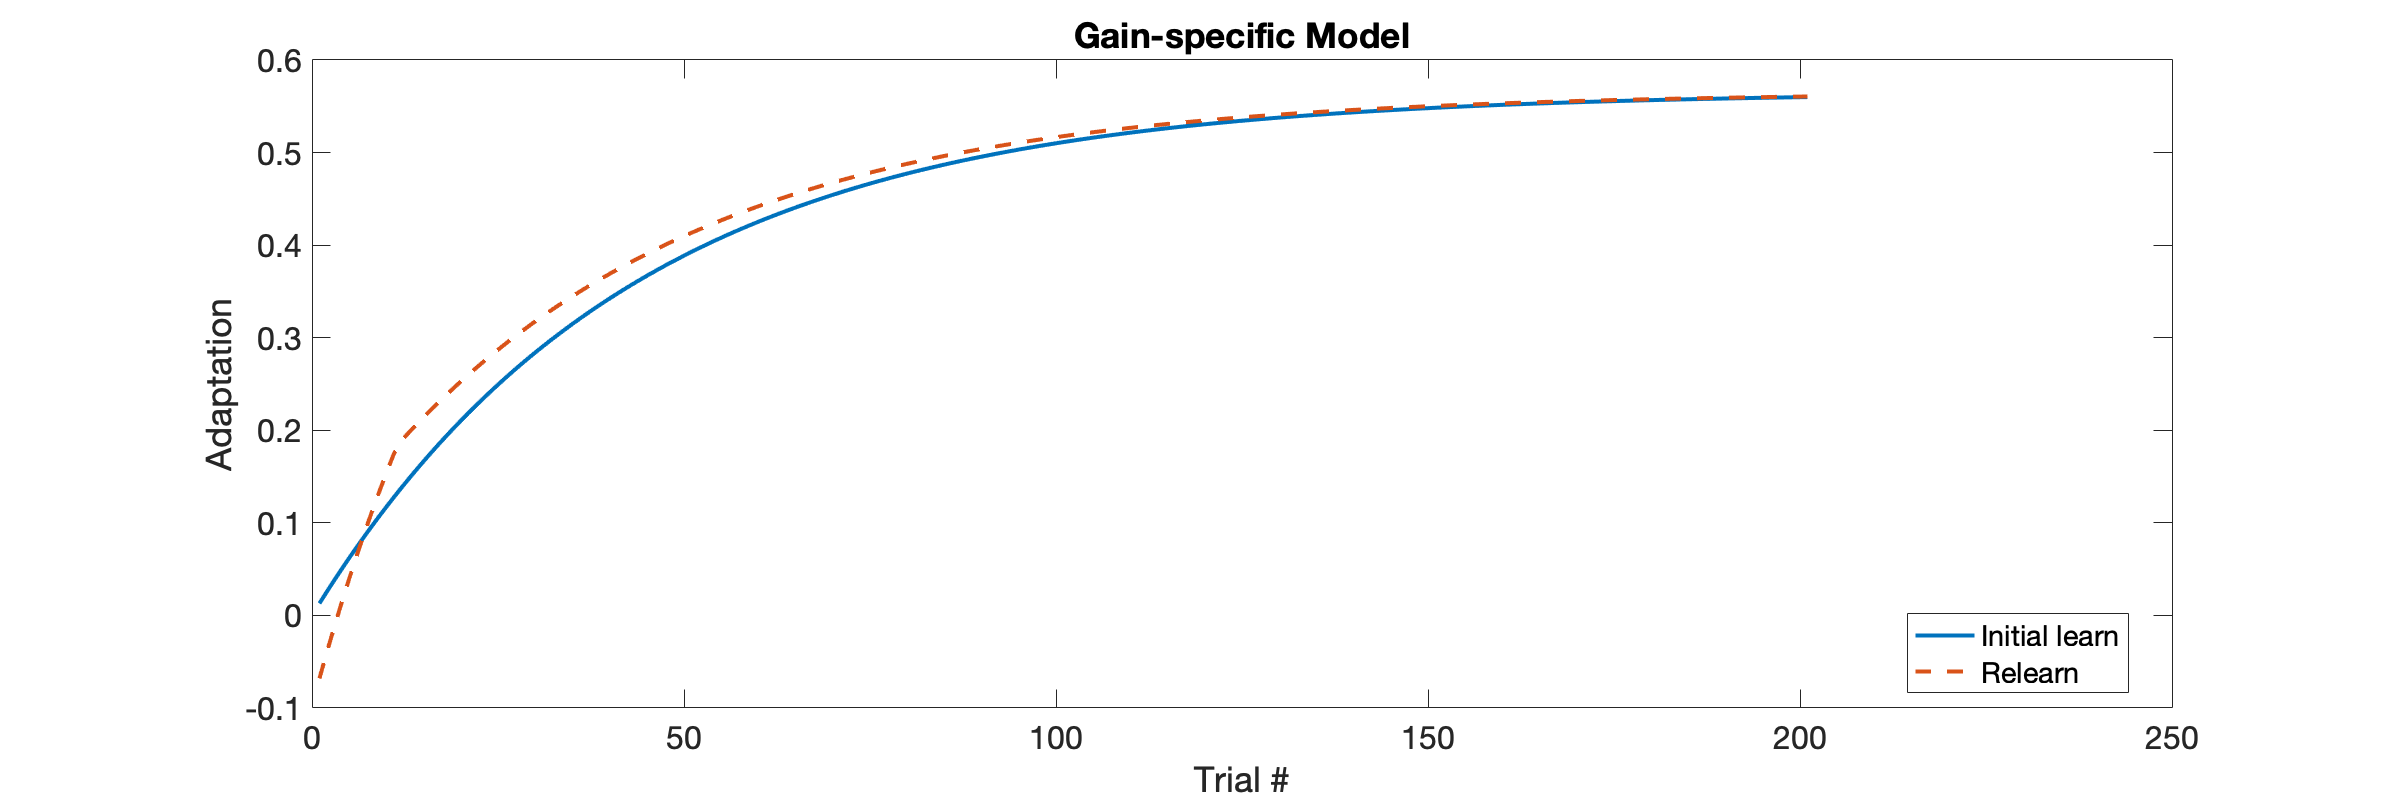

gain_specific(sched4, 'plotSavings', true, 'savingsLen', 200)

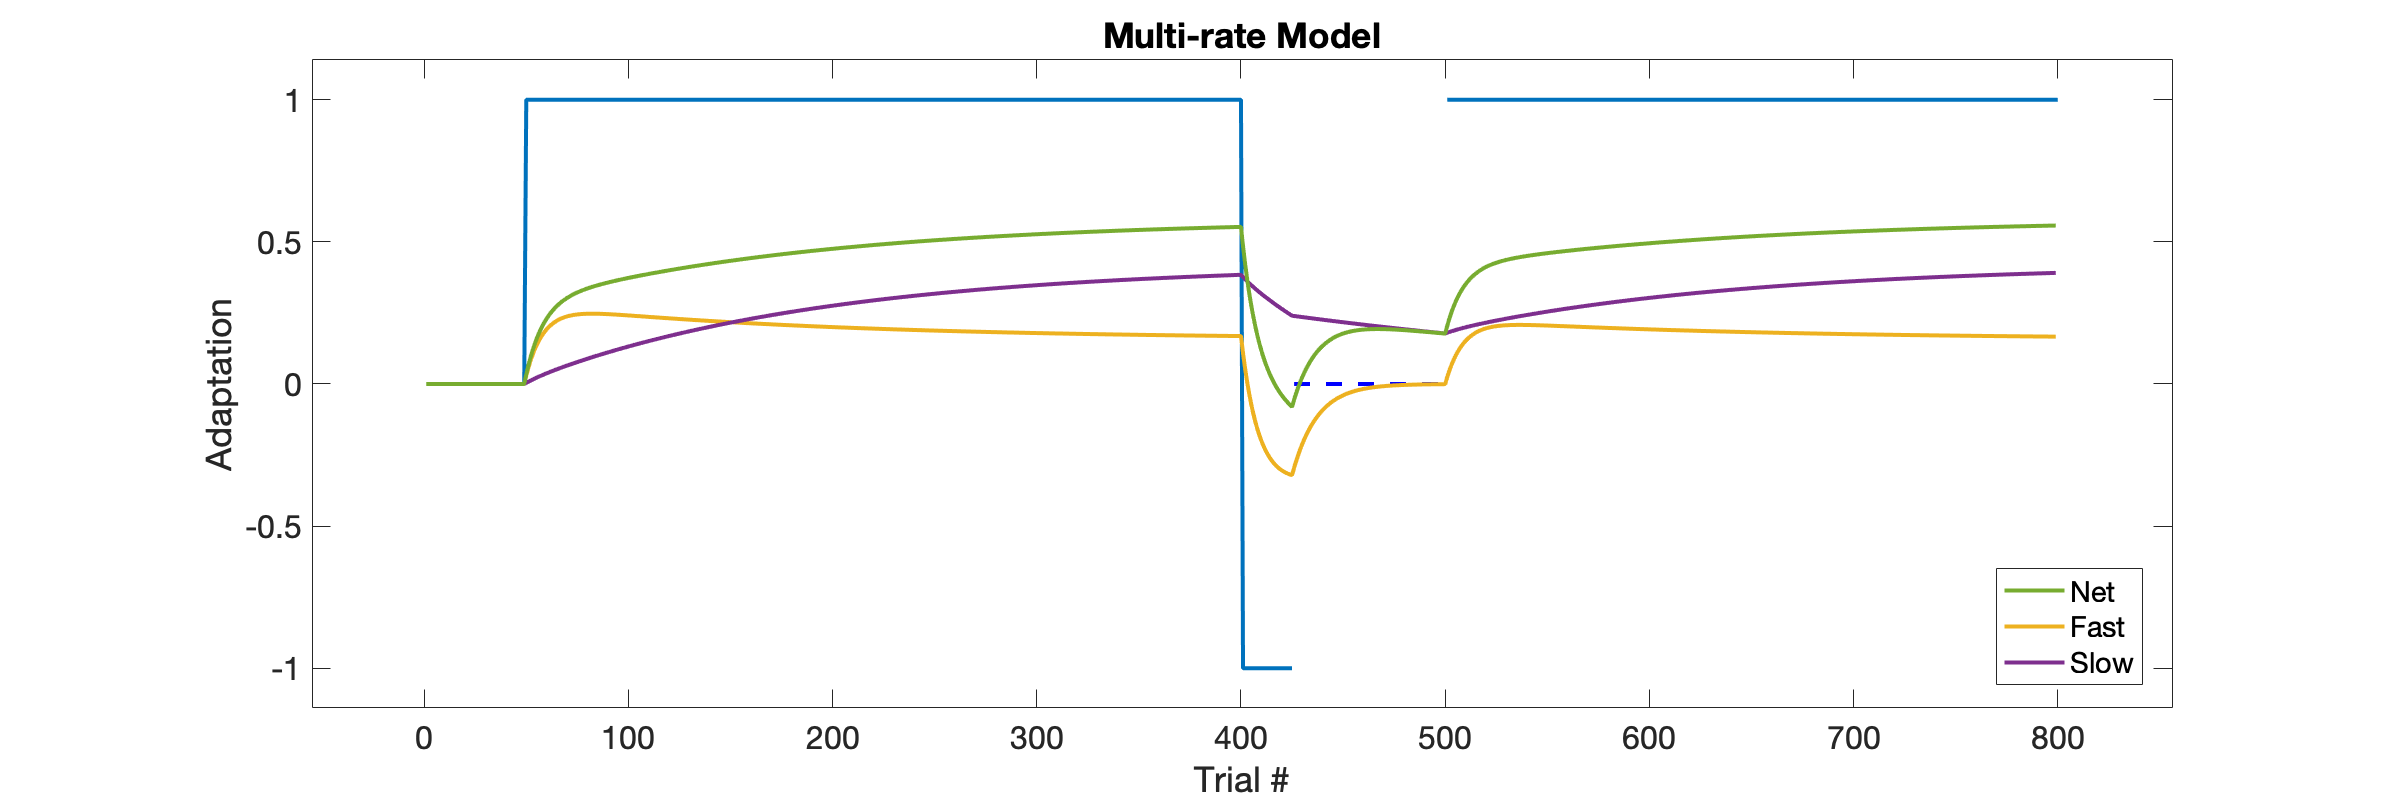

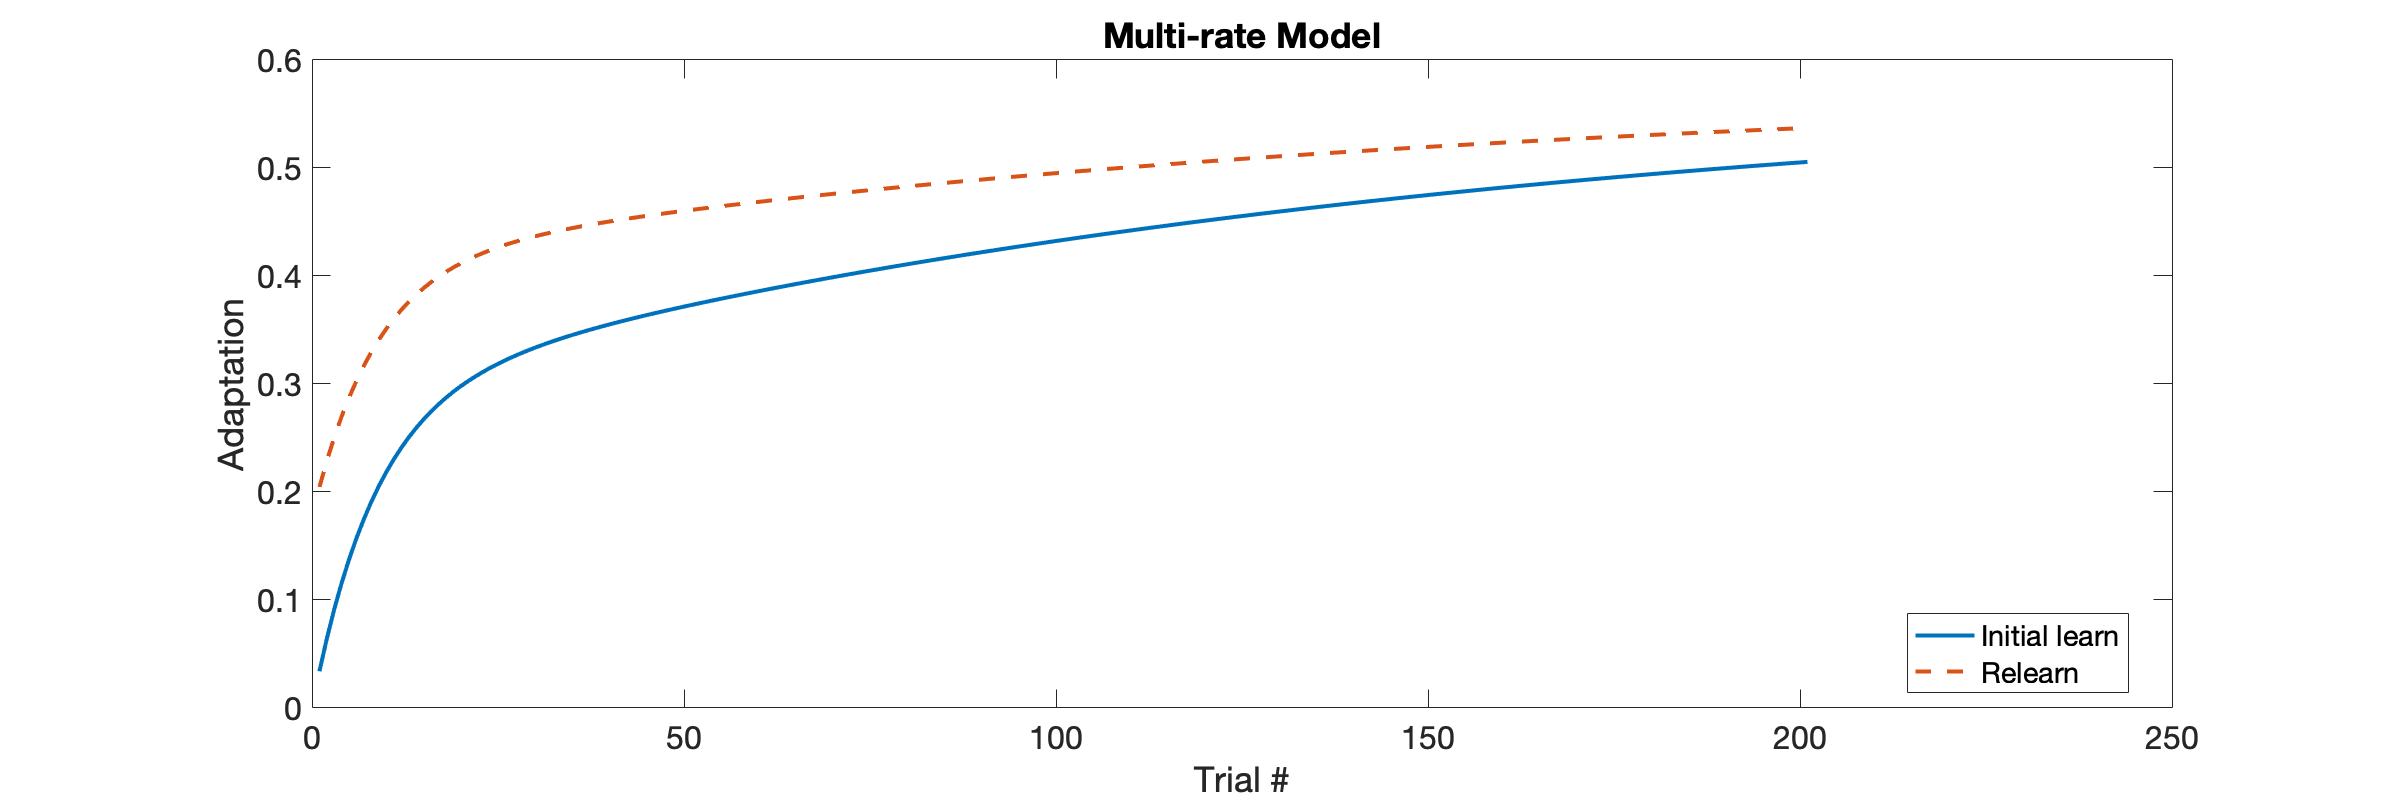

multi_rate(sched4, 'plotSavings', true, 'savingsLen', 200)

## Models

function single_state(perturbation_schedule, varargin)
%{ 
Single state model: x(n+1) = A * x(n) + B * e(n)

INPUTS:
perturbation_schedule: schedule of perturbation 
A: learning rate 
B: forgetting rate 
plotSavings: visualize savings 
savingsLen: length of savings trials 

OUTPUTS:
Visualize of model results 
%}

% parse inputs 
p = inputParser();
addRequired(p, 'perturbation_schedule', @mustBeNumeric)
addParameter(p, 'A', 0.99, @(x) mustBePositive(x) & mustBeGreaterThan(x, 0) & mustBeLessThanorEqual(x, 1));
addParameter(p, 'B', 0.013, @(x) mustBePositive(x) & mustBeGreaterThan(x, 0) & mustBeLessThanorEqual(x, 1));
addParameter(p, 'plotSavings', false, @(x) mustBeA(x, 'logical'))
addParameter(p, 'savingsLen', 300, @mustBeNumeric)
parse(p, perturbation_schedule, varargin{:});

% experiment 
x = 0;
adaptation = nan(size(perturbation_schedule)); 
for i = 1:length(adaptation)-1 % forward model 
    % error 
    if isnan(perturbation_schedule(i))
        er = 0; 
    else 
        er = perturbation_schedule(i) - x;
    end
    % adaptation 
    adaptation(i) = p.Results.A * x + p.Results.B * er;
    % update 
    x = adaptation(i); 
end

% visualize 
figure('position', [300 300 1200 400]);
plot(perturbation_schedule, 'linewidth', 2);
hold on 
if sum(isnan(perturbation_schedule)) > 0
    idx = find(isnan(perturbation_schedule));
    plot(idx, zeros([length(idx), 1]), 'linestyle', '--', 'linewidth', 2, 'color', 'b');
end
n = plot(adaptation, 'linewidth', 2, 'DisplayName', 'Net'); 
xlabel('Trial #'); ylabel('Adaptation'); legend(n, 'location', 'best'); 
axis(gca(), 'padded')
title('Single-state Model'); set(gca, 'fontsize', 16); 

if p.Results.plotSavings
    figure('position', [300 300 1200 400]);
    perturb = find(perturbation_schedule == 1);
    perturb_dx = diff(perturb);
    learn = perturb(1);
    relearn = perturb(find(perturb_dx ~= 1)+1);
    plot(adaptation(learn:learn+p.Results.savingsLen), 'linewidth', 2, 'displayname', 'Initial learn')
    hold on 
    plot(adaptation(relearn:relearn+p.Results.savingsLen), 'linewidth', 2, 'linestyle', '--', 'displayname', 'Relearn')
    xlabel('Trial #'); ylabel('Adaptation'); legend('location', 'best'); 
    title('Single-state Model'); set(gca, 'fontsize', 16); 
end

end

function gain_specific(perturbation_schedule, varargin)
%{ 
Gain specific model 
    x1(n+1) = min(0, [A * x_1(n) + B * e(n)])
    x2(n+1) = max(0, [A * x_2(n) + B * e(n)])
    x = x_1 + x_2

INPUTS:
perturbation_schedule: perturbation schedule 
A_f: learning rate (fast)
A_s: learning rate (slow)
B_f: forgetting rate (fast)
B_s: forgetting rate (slow)
plotSavings: visualize savings 
savingsLen: length of savings trials 

OUTPUT:
Visualization of model for perturbation schedule
%}

% parse inputs 
p = inputParser();
addRequired(p, 'perturbation_schedule', @mustBeNumeric)
addParameter(p, 'A_f', 0.99, @(x) mustBePositive(x) & mustBeGreaterThan(x, 0) & mustBeLessThanorEqual(x, 1));
addParameter(p, 'B_f', 0.013, @(x) mustBePositive(x) & mustBeGreaterThan(x, 0) & mustBeLessThanorEqual(x, 1));
addParameter(p, 'A_s', 0.99, @(x) mustBePositive(x) & mustBeGreaterThan(x, 0) & mustBeLessThanorEqual(x, 1));
addParameter(p, 'B_s', 0.013, @(x) mustBePositive(x) & mustBeGreaterThan(x, 0) & mustBeLessThanorEqual(x, 1));
addParameter(p, 'plotSavings', false, @(x) mustBeA(x, 'logical'))
addParameter(p, 'savingsLen', 300, @mustBeNumeric)
parse(p, perturbation_schedule, varargin{:});

% experiment 
x_1 = 0; x_2 = 0; 
up = nan(size(perturbation_schedule)); 
down = nan(size(perturbation_schedule)); 
net = nan(size(perturbation_schedule)); 
for i = 1:length(net)-1 % forward model 
    % error 
    if isnan(perturbation_schedule(i))
        er = 0; 
    else 
        er = perturbation_schedule(i) - (x_1 + x_2);
    end
    % up 
    up(i) = max([0, p.Results.A_f * x_1 + p.Results.B_f * er]);
    % down 
    down(i) = min([0, p.Results.A_s * x_2 + p.Results.B_s * er]); 
    % net 
    net(i) = up(i) + down(i); 
    % update 
    x_1 = up(i); 
    x_2 = down(i); 
end

% visualize 
figure('position', [300 300 1200 400]);
plot(perturbation_schedule, 'linewidth', 2);
hold on 
if sum(isnan(perturbation_schedule)) > 0
    idx = find(isnan(perturbation_schedule));
    plot(idx, zeros([length(idx), 1]), 'linestyle', '--', 'linewidth', 2, 'color', 'b');
end
u = plot(up, 'linewidth', 2, 'DisplayName', 'Up'); 
d = plot(down, 'linewidth', 2, 'DisplayName', 'Down'); 
n = plot(net, 'linewidth', 2, 'DisplayName', 'Net'); 
xlabel('Trial #'); ylabel('Adaptation'); legend([n, u, d], 'location', 'best'); 
axis(gca(), 'padded')
title('Gain-specific Model'); set(gca, 'fontsize', 16); 

if p.Results.plotSavings
    figure('position', [300 300 1200 400]);
    perturb = find(perturbation_schedule == 1);
    perturb_dx = diff(perturb);
    learn = perturb(1);
    relearn = perturb(find(perturb_dx ~= 1)+1);
    plot(net(learn:learn+p.Results.savingsLen), 'linewidth', 2, 'displayname', 'Initial learn')
    hold on 
    plot(net(relearn:relearn+p.Results.savingsLen), 'linewidth', 2, 'linestyle', '--', 'displayname', 'Relearn')
    xlabel('Trial #'); ylabel('Adaptation'); legend('location', 'best'); 
    title('Gain-specific Model'); set(gca, 'fontsize', 16); 
end

end

function multi_rate(perturbation_schedule, varargin)
%{ 
Multi-rate model 
x_1(n+1) = A_f * x_1(n) + B_f * e(n)
x_2(n+1) = A_s * x_2(n) + B)s * e(n)

INPUTS:
perturbation_schedule: perturbation schedule 
A_f: learning rate (fast)
A_s: learning rate (slow)
B_f: forgetting rate (fast)
B_s: forgetting rate (slow)
plotSavings: visualize savings 
savingsLen: length of savings trials 

OUTPUT:
Visualize of model predictions of perturbation schedule with given parameters
%}

% parse inputs 
p = inputParser();
addRequired(p, 'perturbation_schedule', @mustBeNumeric)
addParameter(p, 'A_f', 0.92, @(x) mustBePositive(x) & mustBeGreaterThan(x, 0) & mustBeLessThanorEqual(x, 1));
addParameter(p, 'B_f', 0.03, @(x) mustBePositive(x) & mustBeGreaterThan(x, 0) & mustBeLessThanorEqual(x, 1));
addParameter(p, 'A_s', 0.996, @(x) mustBePositive(x) & mustBeGreaterThan(x, 0) & mustBeLessThanorEqual(x, 1));
addParameter(p, 'B_s', 0.004, @(x) mustBePositive(x) & mustBeGreaterThan(x, 0) & mustBeLessThanorEqual(x, 1));
addParameter(p, 'plotSavings', false, @(x) mustBeA(x, 'logical'))
addParameter(p, 'savingsLen', 300, @mustBeNumeric)
parse(p, perturbation_schedule, varargin{:});

% experiment 
x_1 = 0; x_2 = 0; 
fast = nan(size(perturbation_schedule)); 
slow = nan(size(perturbation_schedule)); 
net = nan(size(perturbation_schedule)); 
for i = 1:length(net)-1 % forward model 
    % error 
    if isnan(perturbation_schedule(i))
        er = 0; 
    else 
        er = perturbation_schedule(i) - (x_1 + x_2);
    end
    % up 
    fast(i) = p.Results.A_f * x_1 + p.Results.B_f * er;
    % down 
    slow(i) = p.Results.A_s * x_2 + p.Results.B_s * er; 
    % net 
    net(i) = fast(i) + slow(i); 
    % update 
    x_1 = fast(i); 
    x_2 = slow(i); 
end

% visualize 
figure('position', [300 300 1200 400]);
plot(perturbation_schedule, 'linewidth', 2);
hold on 
if sum(isnan(perturbation_schedule)) > 0
    idx = find(isnan(perturbation_schedule));
    plot(idx, zeros([length(idx), 1]), 'linestyle', '--', 'linewidth', 2, 'color', 'b');
end
f = plot(fast, 'linewidth', 2, 'DisplayName', 'Fast'); 
s = plot(slow, 'linewidth', 2, 'DisplayName', 'Slow'); 
n = plot(net, 'linewidth', 2, 'DisplayName', 'Net'); 
xlabel('Trial #'); ylabel('Adaptation'); legend([n, f, s], 'location', 'best'); 
axis(gca(), 'padded')
title('Multi-rate Model'); set(gca, 'fontsize', 16); 

if p.Results.plotSavings
    figure('position', [300 300 1200 400]);
    perturb = find(perturbation_schedule == 1);
    perturb_dx = diff(perturb);
    learn = perturb(1);
    relearn = perturb(find(perturb_dx ~= 1)+1);
    plot(net(learn:learn+p.Results.savingsLen), 'linewidth', 2, 'displayname', 'Initial learn')
    hold on 
    plot(net(relearn:relearn+p.Results.savingsLen), 'linewidth', 2, 'linestyle', '--', 'displayname', 'Relearn')
    xlabel('Trial #'); ylabel('Adaptation'); legend('location', 'best'); 
    title('Multi-rate Model'); set(gca, 'fontsize', 16); 
end

end